% Recoveries
% Export all wells and a QC file (Rseal, Cslow, Rseries) of all 4 protocols.
% Export raw uncorrected leak file as well as raw file.
% QCs in this file - Rseal, Cslow, corrected leak, uncorrected leak, peak
% cut off, mean recovery>1 cut off, inverse slope cut off??


% Variables
LeakCheck = 95000 

LeakCheck = 95000

LeakCheck2 = LeakCheck/50+1

LeakCheck2 = 1901


Rec_control1_start = 1720500 ;
Rec_1ms_start = 2291500 ;
Rec_2ms_start = 2863500 ;
Rec_3ms_start = 3436500 ;
Rec_4ms_start = 4010500 ;
Rec_5ms_start = 4585500 ;
Rec_6ms_start = 5160500 ;
Rec_7ms_start = 5738500 ;

Rec_control2_start = 1720500 ;
Rec_8ms_start = 2875500 ;
Rec_9ms_start = 3454500 ;
Rec_10ms_start = 4034500 ;
Rec_15ms_start = 4619500 ;
Rec_20ms_start = 5209500 ;
Rec_25ms_start = 5804500 ;
Rec_30ms_start = 6404500 ;

Rec_control3_start = 1720500 ;
Rec_35ms_start = 2925500 ;
Rec_40ms_start = 3535500 ;
Rec_45ms_start = 4150500 ;
Rec_50ms_start = 4770500 ;
Rec_75ms_start = 5415500 ;
Rec_100ms_start = 6085500 ; 
Rec_0ms_start = 0 ; %EXCLUDE
%Rec_200ms_start = 5755500 %6265500 %5755500 ;

Rec_control4_start = 1720500 ;
Rec_200ms_start = 3160500 ;
Rec_500ms_start = 4230500 ;
Rec_1000ms_start = 5800500 ;
Rec_0ms_start = 0 ;
Rec_0ms_start = 0 ;
Rec_0ms_start = 0 ; 
Rec_0ms_start = 0 ; %EXCLUDE

Rec_table = table(Rec_control1_start,Rec_1ms_start,Rec_2ms_start,Rec_3ms_start,Rec_4ms_start,Rec_5ms_start,Rec_6ms_start,Rec_7ms_start,Rec_control2_start,Rec_8ms_start,Rec_9ms_start,Rec_10ms_start,Rec_15ms_start,Rec_20ms_start,Rec_25ms_start,Rec_30ms_start,Rec_control3_start,Rec_35ms_start,Rec_40ms_start,Rec_45ms_start,Rec_50ms_start,Rec_75ms_start,Rec_100ms_start,Rec_0ms_start,Rec_control4_start,Rec_200ms_start,Rec_500ms_start,Rec_1000ms_start,Rec_0ms_start,Rec_0ms_start,Rec_0ms_start,Rec_0ms_start) ;
%Rec_table.Properties.VariableNames = ["Rec_control1","Rec_1ms","Rec_2ms","Rec_3ms","Rec_4ms","Rec_5ms","Rec_6ms","Rec_7ms","Rec_control2","Rec_8ms","Rec_9ms","Rec_10ms","Rec_15ms","Rec_20ms","Rec_25ms","Rec_30ms","Rec_control3","Rec_35ms","Rec_40ms","Rec_45ms","Rec_50ms","Rec_75ms","Rec_100ms","Rec_200ms"]

%  QC
Rseal_lowerLim = 500000000 ;
Rseal_upperLim = Inf ;
Cslow_lowerLim = 2e-12 ;
Cslow_upperLim = 30e-12 ;
QCpA_uLim = 40e-12 ;
QCpA_lLim = -40e-12 ;
ControlPeakpA_Lim = -400e-12 ;
Leak_start = 1001 ; % 45ms after step to -120 from -80
Leak_end = 1900 ; % 5ms before end of leak correction step (i.e. mean over 50ms used to QC leak correction - 95 to 145ms)
QCUncorpA_uLim = 0 ;

% Import paths
Parent_dir = 'Z:\Functional_Genomics_Syncropatch\SCN5A\3. VUS\' ;
Exp_dir = '20230609_JM4\' ;
Raw_dir = 'QCd_Wells\' ;
QC_dir = 'QC\' ;
Protocol_dir = ["NaRecInac1_19.59.18\","NaRecInac2_19.59.57\","NaRecInac3_20.00.37\","NaRecInac4_20.01.17\"] ;
%UncorrectedRaw_dir = 'Raw_NoLeakCorrection\' ;

% Export paths
folderdir = fullfile(Parent_dir,Exp_dir,Protocol_dir(1)) ;
mkdir(folderdir,'Recoveries')
recoveries_dir = 'Recoveries\' ;

folderdir = fullfile(Parent_dir,Exp_dir,Protocol_dir(1),recoveries_dir) ;
mkdir(folderdir,'RecoveryPlots')


% Import QC first, if it doesnt pass QC there is no point importing file

opts = delimitedTextImportOptions("NumVariables", 8);

% Specify range and delimiter
opts.DataLines = [3, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["WellID", "CellType", "SealResistance", "Capacitance", "SeriesResistance", "SealResistance1", "Capacitance1", "SeriesResistance1"];
opts.VariableTypes = ["string", "categorical", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "WellID", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["WellID", "CellType"], "EmptyFieldRule", "auto");

% Import the data
Raw_wells_4comb = [] ;
QC_wells_4comb = [] ;
for i = 1:4
    QC_wells_temp = dir(fullfile(Parent_dir,Exp_dir,Protocol_dir(i),QC_dir,'QC.csv')) ;
%    QC_wells_temp2 = QC_wells_temp(:,6:8)
    QC_wells_4comb = [QC_wells_4comb;QC_wells_temp] ;
    Raw_wells_temp = dir(fullfile(Parent_dir,Exp_dir,Protocol_dir(i),Raw_dir,'*.csv')) ;
    Raw_wells_4comb = [Raw_wells_4comb;Raw_wells_temp] ;
end


%   Import of QC sweeps data
for i = 1:4
    fid = fullfile(Parent_dir,Exp_dir,Protocol_dir(i),QC_dir,QC_wells_4comb(i).name);
    fidopen = fopen(fid);
    QCWells_data{1,i} = QC_wells_4comb(i).name ;
    QCWells_data{2,i} = readtable(fid,opts) ;
    fclose("all");
end  


% Clear variables
clear opts



% Filtering for wells which pass QC across ALL 4 protocols

for i = 1:4
    QCWells_temp = QCWells_data{2,i} ;
    QCWells_tempR = QCWells_temp.SealResistance > Rseal_lowerLim ;
    QCWells_temp = QCWells_temp(QCWells_tempR,:) ;
    QCWells_tempC = QCWells_temp.Capacitance > Cslow_lowerLim & QCWells_temp.Capacitance < Cslow_upperLim ;
    QCWells_temp = QCWells_temp(QCWells_tempC,:) ;
    QCWells_temp.Properties.RowNames = QCWells_temp.WellID ;
    QCWells_data{3,i} = QCWells_temp ;
end

QCWells_temp1 = QCWells_data{3,1} ;
QCWells_temp2 = QCWells_data{3,2} ;
QCWells_temp3 = QCWells_data{3,3} ;
QCWells_temp4 = QCWells_data{3,4} ;
QCWells_filter1_2 = QCWells_temp1(contains(QCWells_temp1.Properties.RowNames,QCWells_temp2.Properties.RowNames),:) ;
QCWells_filter1_2_3 = QCWells_filter1_2(contains(QCWells_filter1_2.Properties.RowNames,QCWells_temp3.Properties.RowNames),:) ;
QCWells_filter1_2_3_4 = QCWells_filter1_2_3(contains(QCWells_filter1_2_3.Properties.RowNames,QCWells_temp4.Properties.RowNames),:) 

QCWells_filter1_2_3_4 = 221×8 table
           WellID        CellType         SealResistance    Capacitance    SeriesResistance    SealResistance1    Capacitance1    SeriesResistance1
           ______    _________________    ______________    ___________    ________________    _______________    ____________    _________________

    F01    "F01"     SCN5A_DelQ1077_WT      1.8347e+10      2.4337e-12        8.6299e+06         1.9924e+10        2.4014e-12        8.8675e+06    
    G01    "G01"     SCN5A_DelQ1077_WT      7.2793e+09      2.6306e-12        1.3483e+07         8.3179e+09        2.6412e-12        1.3193e+07    
    H01    "H01"     SCN5A_DelQ1077_WT      6.78



%Boltz_filtered = Boltz_allWells(contains(Boltz_allWells.Properties.RowNames,PeaksAtMV_filterLow_Upp.Properties.RowNames),:) ;


% Extracting wellIDs

WellID_RawID1 = char(Raw_wells_4comb.name) ;
WellID_Raw = string(zeros(384*4,1)) ;
%20221117 n_wells = size(WellID_Raw) ;
n_wells = size(Raw_wells_4comb) ;

for i = 1:n_wells(1) 
    WellID_RawID2(i) = string(WellID_RawID1(i,25:27)) ; %25:27
end

WellID_RawID3 = WellID_RawID2' ;
%WellID_RawID2 = table(WellID_RawID2)

Raw_wells_4comb = struct2table(Raw_wells_4comb) ;
Raw_wells_4comb.WellIDs = WellID_RawID3 ;
Raw_wells_4_filtered = Raw_wells_4comb(contains(Raw_wells_4comb.WellIDs,QCWells_filter1_2_3_4.Properties.RowNames),:) ;
Raw_wells_4_filtered = table2struct(Raw_wells_4_filtered) ;



opts = delimitedTextImportOptions("NumVariables", 5);

% Specify range and delimiter
opts.DataLines = [4, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["SamplePoint", "SampleTimeus", "Var4", "RawDataA1"];
opts.SelectedVariableNames = ["SamplePoint", "SampleTimeus", "RawDataA1"];
opts.VariableTypes = ["double", "double", "string", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Var4", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var4", "EmptyFieldRule", "auto");


% Import the data
n_pass = size(Raw_wells_4_filtered) ;

%   Import of Raw sweeps data
for irec = 1:4
    wellStart = n_pass/4*irec-n_pass/4+1 ;
    wellEnd = wellStart+n_pass/4-1 ;
    LabelRow = (irec*irec)-((irec-1)*(irec-1)) ;
    DataRow = LabelRow+1 ;
    for i = wellStart(1):wellEnd(1)
        fid = fullfile(Parent_dir,Exp_dir,Protocol_dir(irec),Raw_dir,Raw_wells_4_filtered(i).name);
        fidopen = fopen(fid);  
            RawWells_data{1,i} = Raw_wells_4_filtered(i).name ;    
            RawWells_data{2,i} = readtable(fid,opts) ;                 
        fclose("all");         
    end 
end  

clear opts


% Organising
% RawWells_data2 = cell2table(RawWells_data)
% RawWells_data3 = [RawWells_data2{1,1:n_pass(1)/3-1};RawWells_data2{2,1:n_pass(1)/3-1};RawWells_data2{1,n_pass(1)/3:n_pass(1)/3*2-1};RawWells_data2{2,n_pass(1)/3:n_pass(1)/3*2-1};RawWells_data2{1,n_pass(1)/3*2:n_pass(1)-1};RawWells_data2{2,n_pass(1)/3*2:n_pass(1)-1}]
n = n_pass/4 ;
RawWells_data2 = reshape(RawWells_data',n(1),[]) ;

% QC Leak

LeakCheck2 = LeakCheck/50+1

LeakCheck2 = 1901

n_pass = size(RawWells_data2)

n_pass =    221     8


LeakQC = []


LeakQC =

     []




for iii = 1:4 % PLATE
    for i = 1:n_pass(1) %WELL
    RawWells_peaks(i,1) = Raw_wells_4_filtered(i).WellIDs ;
    RawWell_leakDataTemp = RawWells_data2{i,iii+4} ;
    RawWell_leakDataTemp2 = table2array(RawWell_leakDataTemp(LeakCheck2:LeakCheck2+100,3)) ;

    [mean_temp] = mean(RawWell_leakDataTemp2) ;
    LeakQC = [LeakQC;mean_temp] ;
    end
end

LeakQC = reshape(LeakQC,n_pass(1),[]) ;
LeakQC_tab = array2table(LeakQC) ;
LeakQC_tab.Properties.RowNames = RawWells_peaks(:,1)  ;

LeakQC_tabFilter1 = LeakQC_tab.LeakQC1 < QCpA_uLim & LeakQC_tab.LeakQC1 > QCpA_lLim ;
LeakQC_tabFilter1 = LeakQC_tab(LeakQC_tabFilter1,:) ;
LeakQC_tabFilter2 = LeakQC_tabFilter1.LeakQC2 < QCpA_uLim & LeakQC_tabFilter1.LeakQC2 > QCpA_lLim ;
LeakQC_tabFilter2 = LeakQC_tabFilter1(LeakQC_tabFilter2,:) ;
LeakQC_tabFilter3 = LeakQC_tabFilter2.LeakQC3 < QCpA_uLim & LeakQC_tabFilter2.LeakQC3 > QCpA_lLim ;
LeakQC_tabFilter3 = LeakQC_tabFilter2(LeakQC_tabFilter3,:) ;
LeakQC_tabFilter4 = LeakQC_tabFilter3.LeakQC4 < QCpA_uLim & LeakQC_tabFilter3.LeakQC4 > QCpA_lLim ;
LeakQC_tabFilter4 = LeakQC_tabFilter3(LeakQC_tabFilter4,:) ;

% Extracting values at times of interest per recovery
% Final layout of cell - variables: wellID, control1, 1ms, 2ms,
% 3ms, ....7ms
% Final layout of cell - rows = wells that have passed QC

Rec_table2 = reshape(table2cell(Rec_table),8,4) ;
n_rec = size(Rec_table2) ;
n_pass = size(RawWells_data2) ;

for iii = 1:4 % PLATE
    for i = 1:n_pass(1) %WELL
    RawWells_peaks(i,1) = Raw_wells_4_filtered(i).WellIDs ;
    RawWell_temp = RawWells_data2{i,iii+4} ;
    for ii = 1:n_rec(1) % RECOVERY 
        R_start = cell2mat(Rec_table2(ii,iii)) ;
        R_start_idx = R_start/50+1 ;
        R_end_idx = R_start_idx+200 ;
        Rec_range = RawWell_temp(R_start_idx:R_end_idx,3) ;
        Rec_min = min(table2array(Rec_range)) ;
        RawWells_peaks(i,ii+8*(iii-1)+1) = Rec_min ;        
    end
    end 
end


% Normalising to control step and conversion to table

s = size(RawWells_peaks)

s =    221    33


%for i = 1:8
RawWells_peaksTab = array2table(str2double(RawWells_peaks(:,2:end))) ;
RawWells_peaksTab.Properties.RowNames = RawWells_peaks(:,1) ;

RawWells_peaksTab_PeaksQC1 = RawWells_peaksTab.Var1 < ControlPeakpA_Lim  ;
RawWells_peaksTab_PeaksQC1 = RawWells_peaksTab(RawWells_peaksTab_PeaksQC1,:) ;
RawWells_peaksTab_PeaksQC2 = RawWells_peaksTab_PeaksQC1.Var9 < ControlPeakpA_Lim  ;
RawWells_peaksTab_PeaksQC2 = RawWells_peaksTab_PeaksQC1(RawWells_peaksTab_PeaksQC2,:) ;
RawWells_peaksTab_PeaksQC3 = RawWells_peaksTab_PeaksQC2.Var17 < ControlPeakpA_Lim  ;
RawWells_peaksTab_PeaksQC3 = RawWells_peaksTab_PeaksQC2(RawWells_peaksTab_PeaksQC3,:) ;
RawWells_peaksTab_PeaksQC4 = RawWells_peaksTab_PeaksQC3.Var25 < ControlPeakpA_Lim  ;
RawWells_peaksTab_PeaksQC4 = RawWells_peaksTab_PeaksQC3(RawWells_peaksTab_PeaksQC4,:) ;

RawWells_peaksArr = table2array(RawWells_peaksTab_PeaksQC4) ;
Peaks_P1_Norm = RawWells_peaksArr(:,2:8)./RawWells_peaksArr(:,1) ;
Peaks_P2_Norm = RawWells_peaksArr(:,10:16)./RawWells_peaksArr(:,9) ;
Peaks_P3_Norm = RawWells_peaksArr(:,18:24)./RawWells_peaksArr(:,17) ;
Peaks_P4_Norm = RawWells_peaksArr(:,26:32)./RawWells_peaksArr(:,25) ;
Peaks_Pall_Norm = [Peaks_P1_Norm,Peaks_P2_Norm,Peaks_P3_Norm,Peaks_P4_Norm] ;
Peaks_Pall_NormTab = array2table(Peaks_Pall_Norm) ;
Peaks_Pall_NormTab.Properties.RowNames = RawWells_peaksTab_PeaksQC4.Properties.RowNames ;


Peaks_Pall_NormTab.Peaks_Pall_Norm21 = [] ;
Peaks_Pall_NormTab.Peaks_Pall_Norm25 = [] ;
Peaks_Pall_NormTab.Peaks_Pall_Norm26 = [] ;
Peaks_Pall_NormTab.Peaks_Pall_Norm27 = [] ;
Peaks_Pall_NormTab.Peaks_Pall_Norm28 = [] ;


% Filtering bad wells - when each recovery peak is the ~same size as
% controls, the norm data would show ~1. This step is to remove those bad data.

% UPDATED: also filter out the wells not passing leak correction check

Peaks_Pall_mean = mean(Peaks_Pall_Norm')' ;
Peaks_Pall_mean = array2table(Peaks_Pall_mean) ;
Peaks_Pall_mean.Properties.RowNames = RawWells_peaksTab_PeaksQC4.Properties.RowNames 

Peaks_Pall_mean = 86×1 table
           Peaks_Pall_mean
           _______________

    A07        0.51315    
    A08        0.45138    
    A10        0.53534    
    A12        0.45099    
    A13        0.55015    
    A16        0.18932    
    A19        0.48922    
    A20        0.45824    
    B07        0.53842    
    B08         0.5403    
    B11        0.51534    
    B18        0.65205    
    B20        0.54722    
    B21        0.54965    
    C08        0.51502    
    C13        0.57424    


Peaks_Pall_meanF = Peaks_Pall_mean.Peaks_Pall_mean < 1 ;
Peaks_Pall_meanF = Peaks_Pall_mean(Peaks_Pall_meanF,:) ;

Peaks_Pall_filterM = Peaks_Pall_NormTab(contains(Peaks_Pall_NormTab.Properties.RowNames,Peaks_Pall_meanF.Properties.RowNames),:) ;
Peaks_Pall_filterM2 = Peaks_Pall_filterM(contains(Peaks_Pall_filterM.Properties.RowNames,LeakQC_tabFilter3.Properties.RowNames),:) ;


% cant use slope to filter in case there is a one-off rec that is out of
% place



time = [1,2,3,4,5,6,7,8,9,10,15,20,25,30,35,40,45,50,75,100,200,500,1000]

time =            1           2           3           4           5           6           7           8           9          10          15          20          25          30          35          40          45          50          75         100         200         500        1000


time = time'

time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


%SpanFast = '(Plateau-Y0)*PercentFast*.01'
%SpanSlow = '(Plateau-Y0)*(100-PercentFast)*.01'
%Y = 'Y0+ SpanFast*(1-exp(-KFast*X)) + SpanSlow*(1-exp(-KSlow*X))'
%singleExpY=Y0 + (Plateau-Y0)*(1-exp(-K*x))
  

DXfitdata_KFast = [] ;
DXfitdata_KSlow = [] ;
DXfitdata_TauFast = [] ;
DXfitdata_TauSlow = [] ;
DXfitdata_HalfTimes = []


DXfitdata_HalfTimes =

     []



DXfitdata_adjR2 = [] ;

SXfitdata_K = [] ;
SXfitdata_Tau = [] ;
SXfitdata_HalfTimes = []


SXfitdata_HalfTimes =

     []



SXfitdata_adjR2 = [] ;

n_wells = size(Peaks_Pall_filterM2)

n_wells =     86    23


y1 =     0.0814
    0.1339
    0.2040
    0.2804
    0.3617
    0.4018
    0.4531
    0.4740
    0.5210
    0.5426


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1144  (0.1064, 0.1224)
       KSlow =     0.00694  (0.003952, 0.009927)
       PercentFast =       76.72  (73.38, 80.06)
       Plateau =       1.003  (0.9797, 1.027)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0036
       rsquare: 0.9979
           dfe: 19
    adjrsquare: 0.9976
          rmse: 0.0138


DXci =     0.1064    0.0040   73.3776    0.9797       NaN
    0.1224    0.0099   80.0554    1.0266       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.08963  (0.0782, 0.1011)
       Plateau =      0.8935  (0.86, 0.9269)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0456
       rsquare: 0.9738
           dfe: 21
    adjrsquare: 0.9726
          rmse: 0.0466


y1 =     0.2449
    0.1618
    0.1416
    0.1977
    0.2337
    0.2787
    0.3056
    0.3473
    0.3963
    0.4149


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       27.13  (-Inf, Inf)
       KSlow =     0.03679  (0.02726, 0.04632)
       PercentFast =       14.96  (8.05, 21.88)
       Plateau =      0.9158  (0.8587, 0.9729)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0575
       rsquare: 0.9651
           dfe: 19
    adjrsquare: 0.9596
          rmse: 0.0550


DXci =       -Inf    0.0273    8.0495    0.8587       NaN
       Inf    0.0463   21.8787    0.9729       NaN


DXcii = 2

singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.05801  (0.04537, 0.07065)
       Plateau =      0.8651  (0.8035, 0.9268)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.1119
       rsquare: 0.9320
           dfe: 21
    adjrsquare: 0.9288
          rmse: 0.0730


y1 =     0.1734
    0.1897
    0.2385
    0.3089
    0.3767
    0.4065
    0.4553
    0.4973
    0.5403
    0.5538


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       10.35  (-2.458e+04, 2.46e+04)
       KSlow =     0.07589  (0.06384, 0.08793)
       PercentFast =       11.03  (4.876, 17.19)
       Plateau =      0.9239  (0.8989, 0.9489)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0182
       rsquare: 0.9887
           dfe: 19
    adjrsquare: 0.9869
          rmse: 0.0309


DXci = 1.0e+04 *

   -2.4581    0.0000    0.0005    0.0001       NaN
    2.4601    0.0000    0.0017    0.0001       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.09647  (0.08602, 0.1069)
       Plateau =      0.9068  (0.8783, 0.9353)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0346
       rsquare: 0.9785
           dfe: 21
    adjrsquare: 0.9775
          rmse: 0.0406


y1 =     0.0837
    0.0860
    0.1380
    0.1788
    0.2240
    0.2761
    0.3134
    0.3488
    0.3840
    0.3950


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.0744  (0.06861, 0.08018)
       KSlow =    0.004896  (0.002828, 0.006963)
       PercentFast =       72.34  (68.83, 75.85)
       Plateau =       1.022  (0.9932, 1.05)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0036
       rsquare: 0.9982
           dfe: 19
    adjrsquare: 0.9979
          rmse: 0.0137


DXci =     0.0686    0.0028   68.8331    0.9932       NaN
    0.0802    0.0070   75.8488    1.0501       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.05374  (0.04626, 0.06122)
       Plateau =       0.901  (0.8591, 0.9429)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0488
       rsquare: 0.9756
           dfe: 21
    adjrsquare: 0.9744
          rmse: 0.0482


y1 =     0.0807
    0.1944
    0.2980
    0.3956
    0.4559
    0.5153
    0.5441
    0.5994
    0.6080
    0.6327


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1755  (0.1578, 0.1932)
       KSlow =    0.009611  (0.005169, 0.01405)
       PercentFast =       74.37  (70.05, 78.68)
       Plateau =      0.9946  (0.9665, 1.023)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0066
       rsquare: 0.9953
           dfe: 19
    adjrsquare: 0.9946
          rmse: 0.0186


DXci =     0.1578    0.0052   70.0537    0.9665       NaN
    0.1932    0.0141   78.6829    1.0226       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1317  (0.1122, 0.1513)
       Plateau =      0.8761  (0.8406, 0.9116)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0637
       rsquare: 0.9547
           dfe: 21
    adjrsquare: 0.9525
          rmse: 0.0551


y1 =     0.1677
    0.1192
    0.1051
    0.0808
    0.0768
    0.0727
    0.0828
    0.0660
    0.0681
    0.0702


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       30.49  (-Inf, Inf)
       KSlow =     0.00204  (0.001531, 0.002549)
       PercentFast =       4.377  (3.058, 5.695)
       Plateau =       1.418  (1.258, 1.579)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0213
       rsquare: 0.9889
           dfe: 19
    adjrsquare: 0.9871
          rmse: 0.0335


DXci =       -Inf    0.0015    3.0577    1.2577       NaN
       Inf    0.0025    5.6954    1.5792       NaN


DXcii = 2

singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =    0.002865  (0.002066, 0.003665)
       Plateau =       1.286  (1.121, 1.452)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0709
       rsquare: 0.9630
           dfe: 21
    adjrsquare: 0.9612
          rmse: 0.0581


y1 =     0.1216
    0.1405
    0.2027
    0.2730
    0.3297
    0.3919
    0.4243
    0.4377
    0.4775
    0.5093


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1277  (0.117, 0.1385)
       KSlow =    0.006802  (0.004659, 0.008945)
       PercentFast =       66.44  (63.14, 69.73)
       Plateau =       1.013  (0.9872, 1.039)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0044
       rsquare: 0.9972
           dfe: 19
    adjrsquare: 0.9967
          rmse: 0.0152


DXci =     0.1170    0.0047   63.1442    0.9872       NaN
    0.1385    0.0089   69.7340    1.0391       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.08528  (0.06865, 0.1019)
       Plateau =      0.8527  (0.8033, 0.9021)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0959
       rsquare: 0.9388
           dfe: 21
    adjrsquare: 0.9359
          rmse: 0.0676


y1 =     0.0880
    0.0813
    0.1377
    0.1806
    0.2325
    0.2619
    0.3160
    0.3573
    0.4090
    0.4270


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =     0.07235  (0.06634, 0.07836)
       KSlow =     0.00334  (0.000471, 0.00621)
       PercentFast =       80.18  (76.19, 84.16)
       Plateau =      0.9933  (0.9431, 1.043)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0057
       rsquare: 0.9971
           dfe: 19
    adjrsquare: 0.9966
          rmse: 0.0173


DXci =     0.0663    0.0005   76.1939    0.9431       NaN
    0.0784    0.0062   84.1602    1.0435       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.06007  (0.05353, 0.0666)
       Plateau =      0.8881  (0.8568, 0.9194)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0296
       rsquare: 0.9849
           dfe: 21
    adjrsquare: 0.9842
          rmse: 0.0376


y1 =     0.0512
    0.1321
    0.2277
    0.3083
    0.3786
    0.4453
    0.4906
    0.5346
    0.5714
    0.6007


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1194  (0.1096, 0.1293)
       KSlow =    0.006223  (0.001552, 0.01089)
       PercentFast =       82.25  (78.15, 86.35)
       Plateau =       1.006  (0.9733, 1.039)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0065
       rsquare: 0.9964
           dfe: 19
    adjrsquare: 0.9958
          rmse: 0.0185


DXci =     0.1096    0.0016   78.1508    0.9733       NaN
    0.1293    0.0109   86.3491    1.0391       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1015  (0.09085, 0.1122)
       Plateau =       0.914  (0.8864, 0.9416)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0336
       rsquare: 0.9814
           dfe: 21
    adjrsquare: 0.9805
          rmse: 0.0400


y1 =     0.1029
    0.1625
    0.2347
    0.3141
    0.3863
    0.4567
    0.4892
    0.5308
    0.5518
    0.5852


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1334  (0.1188, 0.1481)
       KSlow =     0.01454  (0.007192, 0.0219)
       PercentFast =        76.1  (69.5, 82.7)
       Plateau =      0.9845  (0.9629, 1.006)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0047
       rsquare: 0.9972
           dfe: 19
    adjrsquare: 0.9968
          rmse: 0.0156


DXci =     0.1188    0.0072   69.5043    0.9629       NaN
    0.1481    0.0219   82.7005    1.0062       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =       0.101  (0.09019, 0.1119)
       Plateau =      0.9096  (0.8816, 0.9376)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0344
       rsquare: 0.9796
           dfe: 21
    adjrsquare: 0.9786
          rmse: 0.0405


y1 =     0.1208
    0.1541
    0.2296
    0.2991
    0.3807
    0.4260
    0.4713
    0.4969
    0.5377
    0.5597


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1368  (0.1269, 0.1468)
       KSlow =    0.008715  (0.005596, 0.01183)
       PercentFast =       74.29  (70.91, 77.68)
       Plateau =      0.9724  (0.9521, 0.9928)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0032
       rsquare: 0.9978
           dfe: 19
    adjrsquare: 0.9975
          rmse: 0.0131


DXci =     0.1269    0.0056   70.9104    0.9521       NaN
    0.1468    0.0118   77.6769    0.9928       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1035  (0.08898, 0.118)
       Plateau =        0.86  (0.8256, 0.8945)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0529
       rsquare: 0.9646
           dfe: 21
    adjrsquare: 0.9629
          rmse: 0.0502


y1 =     0.0907
    0.3599
    0.5263
    0.6400
    0.6930
    0.7410
    0.7730
    0.8002
    0.8088
    0.8170


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =    0.007695  (-0.00388, 0.01927)
       KSlow =      0.2874  (0.2455, 0.3294)
       PercentFast =       12.55  (6.566, 18.54)
       Plateau =      0.9973  (0.9438, 1.051)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0213
       rsquare: 0.9793
           dfe: 19
    adjrsquare: 0.9760
          rmse: 0.0335


DXci =    -0.0039    0.2455    6.5663    0.9438       NaN
    0.0193    0.3294   18.5428    1.0508       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.2554  (0.2241, 0.2868)
       Plateau =      0.9238  (0.8986, 0.9489)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0404
       rsquare: 0.9607
           dfe: 21
    adjrsquare: 0.9589
          rmse: 0.0438


y1 =     0.1850
    0.2581
    0.3293
    0.3719
    0.4309
    0.4756
    0.5224
    0.5734
    0.5933
    0.6071


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.2181  (0.1757, 0.2606)
       KSlow =     0.01941  (0.01146, 0.02736)
       PercentFast =        64.2  (56.23, 72.16)
       Plateau =      0.9687  (0.9396, 0.9978)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0099
       rsquare: 0.9919
           dfe: 19
    adjrsquare: 0.9907
          rmse: 0.0229


DXci =     0.1757    0.0115   56.2297    0.9396       NaN
    0.2606    0.0274   72.1618    0.9978       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1279  (0.1069, 0.149)
       Plateau =      0.8671  (0.828, 0.9063)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0764
       rsquare: 0.9380
           dfe: 21
    adjrsquare: 0.9351
          rmse: 0.0603


y1 =     0.2100
    0.2420
    0.3167
    0.3666
    0.4377
    0.4769
    0.5089
    0.5587
    0.5587
    0.5979


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1893  (0.1532, 0.2253)
       KSlow =     0.01283  (0.005585, 0.02008)
       PercentFast =       67.89  (60.12, 75.65)
       Plateau =      0.9972  (0.9568, 1.038)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0157
       rsquare: 0.9877
           dfe: 19
    adjrsquare: 0.9857
          rmse: 0.0288


DXci =     0.1532    0.0056   60.1233    0.9568       NaN
    0.2253    0.0201   75.6508    1.0376       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1234  (0.1014, 0.1454)
       Plateau =      0.8732  (0.8301, 0.9163)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0908
       rsquare: 0.9288
           dfe: 21
    adjrsquare: 0.9254
          rmse: 0.0658


y1 =     0.0825
    0.1375
    0.2075
    0.2925
    0.3425
    0.3925
    0.4125
    0.4874
    0.5100
    0.5151


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1161  (0.1061, 0.1262)
       KSlow =    0.009073  (0.005825, 0.01232)
       PercentFast =       70.86  (66.65, 75.07)
       Plateau =       1.029  (1.006, 1.052)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0041
       rsquare: 0.9978
           dfe: 19
    adjrsquare: 0.9974
          rmse: 0.0147


DXci =     0.1061    0.0058   66.6510    1.0061       NaN
    0.1262    0.0123   75.0723    1.0517       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.08157  (0.06949, 0.09365)
       Plateau =      0.9115  (0.871, 0.9519)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0624
       rsquare: 0.9660
           dfe: 21
    adjrsquare: 0.9644
          rmse: 0.0545


y1 =     0.1752
    0.2124
    0.3204
    0.4088
    0.4726
    0.5381
    0.5929
    0.5699
    0.6152
    0.6479


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1996  (0.1643, 0.2348)
       KSlow =     0.02154  (0.01104, 0.03204)
       PercentFast =       70.31  (61.44, 79.17)
       Plateau =       0.986  (0.9595, 1.013)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0086
       rsquare: 0.9937
           dfe: 19
    adjrsquare: 0.9927
          rmse: 0.0213


DXci =     0.1643    0.0110   61.4412    0.9595       NaN
    0.2348    0.0320   79.1714    1.0126       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1336  (0.1163, 0.1508)
       Plateau =      0.9066  (0.8748, 0.9385)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0516
       rsquare: 0.9624
           dfe: 21
    adjrsquare: 0.9606
          rmse: 0.0496


y1 =     0.0486
    0.0705
    0.0714
    0.0676
    0.0724
    0.0724
    0.0752
    0.0798
    0.0859
    0.0900


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       61.94  (-Inf, Inf)
       KSlow =    0.003067  (0.002909, 0.003226)
       PercentFast =        4.72  (4.29, 5.15)
       Plateau =       1.196  (1.173, 1.22)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0014
       rsquare: 0.9992
           dfe: 19
    adjrsquare: 0.9991
          rmse: 0.0085


DXci =       -Inf    0.0029    4.2899    1.1727       NaN
       Inf    0.0032    5.1499    1.2203       NaN


DXcii = 2

singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =    0.004091  (0.003368, 0.004814)
       Plateau =       1.128  (1.041, 1.215)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0371
       rsquare: 0.9792
           dfe: 21
    adjrsquare: 0.9782
          rmse: 0.0421


y1 =     0.0902
    0.2000
    0.3000
    0.3967
    0.4656
    0.5213
    0.5754
    0.5921
    0.6086
    0.6365


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1716  (0.159, 0.1842)
       KSlow =    0.007442  (0.004045, 0.01084)
       PercentFast =          78  (74.84, 81.17)
       Plateau =      0.9862  (0.961, 1.011)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0045
       rsquare: 0.9967
           dfe: 19
    adjrsquare: 0.9961
          rmse: 0.0154


DXci =     0.1590    0.0040   74.8354    0.9610       NaN
    0.1842    0.0108   81.1695    1.0113       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1382  (0.12, 0.1565)
       Plateau =      0.8718  (0.8407, 0.9029)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0500
       rsquare: 0.9630
           dfe: 21
    adjrsquare: 0.9613
          rmse: 0.0488


y1 =     0.0659
    0.1804
    0.3006
    0.3957
    0.4829
    0.5363
    0.5915
    0.6310
    0.6593
    0.6820


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1642  (0.1478, 0.1805)
       KSlow =    0.007914  (0.001527, 0.0143)
       PercentFast =       82.45  (77.72, 87.17)
       Plateau =      0.9947  (0.9599, 1.03)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0090
       rsquare: 0.9941
           dfe: 19
    adjrsquare: 0.9931
          rmse: 0.0217


DXci =     0.1478    0.0015   77.7234    0.9599       NaN
    0.1805    0.0143   87.1706    1.0295       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1394  (0.1239, 0.1549)
       Plateau =      0.9047  (0.8776, 0.9318)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0380
       rsquare: 0.9748
           dfe: 21
    adjrsquare: 0.9736
          rmse: 0.0426


y1 =     0.0795
    0.1420
    0.1856
    0.2651
    0.3239
    0.3826
    0.4053
    0.4591
    0.4758
    0.5130


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1183  (0.1071, 0.1294)
       KSlow =     0.01178  (0.008066, 0.01549)
       PercentFast =       68.18  (63.26, 73.11)
       Plateau =      0.9923  (0.9733, 1.011)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0032
       rsquare: 0.9982
           dfe: 19
    adjrsquare: 0.9979
          rmse: 0.0131


DXci =     0.1071    0.0081   63.2580    0.9733       NaN
    0.1294    0.0155   73.1112    1.0112       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.07864  (0.06729, 0.09)
       Plateau =        0.89  (0.8511, 0.9288)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0560
       rsquare: 0.9682
           dfe: 21
    adjrsquare: 0.9667
          rmse: 0.0516


y1 =     0.1156
    0.1893
    0.2542
    0.3418
    0.3990
    0.4664
    0.5096
    0.5349
    0.5910
    0.6097


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =        0.14  (0.1316, 0.1484)
       KSlow =    0.009467  (0.006148, 0.01278)
       PercentFast =       77.93  (74.93, 80.93)
       Plateau =       1.001  (0.9837, 1.018)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0024
       rsquare: 0.9985
           dfe: 19
    adjrsquare: 0.9982
          rmse: 0.0113


DXci =     0.1316    0.0061   74.9321    0.9837       NaN
    0.1484    0.0128   80.9302    1.0183       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1106  (0.0978, 0.1235)
       Plateau =      0.9041  (0.8745, 0.9337)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0405
       rsquare: 0.9745
           dfe: 21
    adjrsquare: 0.9732
          rmse: 0.0439


y1 =     0.0806
    0.0645
    0.0599
    0.0530
    0.0576
    0.2005
    0.0484
    0.0746
    0.0572
    0.0672


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       30.49  (-Inf, Inf)
       KSlow =    0.002562  (0.001962, 0.003161)
       PercentFast =       3.924  (2.292, 5.555)
       Plateau =       1.278  (1.154, 1.402)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0241
       rsquare: 0.9871
           dfe: 19
    adjrsquare: 0.9850
          rmse: 0.0356


DXci = 2×5
      -Inf    0.0020    2.2919    1.1543       NaN
       Inf    0.0032    5.5553    1.4015       NaN


DXcii = 2

singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =    0.003344  (0.002567, 0.004122)
       Plateau =       1.198  (1.073, 1.322)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0547
       rsquare: 0.9707
           dfe: 21
    adjrsquare: 0.9693
          rmse: 0.0511


y1 = 23×1
    0.2691
    0.2065
    0.3830
    0.5057
    0.6146
    0.6584
    0.6897
    0.7309
    0.7531
    0.7766


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.2425  (-61.03, 61.51)
       KSlow =      0.1951  (-4.022, 4.412)
       PercentFast =       7.855  (-1.816e+04, 1.818e+04)
       Plateau =      0.9101  (0.8747, 0.9455)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0464
       rsquare: 0.9572
           dfe: 19
    adjrsquare: 0.9505
          rmse: 0.0494


DXci = 2×5
1.0e+04 *

   -0.0061   -0.0004   -1.8163    0.0001       NaN
    0.0062    0.0004    1.8178    0.0001       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1986  (0.1735, 0.2236)
       Plateau =      0.9099  (0.8818, 0.938)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0465
       rsquare: 0.9572
           dfe: 21
    adjrsquare: 0.9551
          rmse: 0.0470


y1 = 23×1
    0.1475
    0.1926
    0.2643
    0.2992
    0.3730
    0.4078
    0.4549
    0.5174
    0.5460
    0.5665


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1217  (0.1122, 0.1312)
       KSlow =    0.006494  (0.002821, 0.01017)
       PercentFast =          79  (75.29, 82.72)
       Plateau =       1.014  (0.9848, 1.043)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0054
       rsquare: 0.9967
           dfe: 19
    adjrsquare: 0.9962
          rmse: 0.0168


DXci = 2×5
    0.1122    0.0028   75.2867    0.9848       NaN
    0.1312    0.0102   82.7150    1.0434       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.09926  (0.08727, 0.1112)
       Plateau =      0.9068  (0.8753, 0.9384)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0432
       rsquare: 0.9736
           dfe: 21
    adjrsquare: 0.9723
          rmse: 0.0454


y1 = 23×1
    0.1489
    0.2036
    0.2918
    0.3708
    0.4194
    0.4802
    0.5562
    0.5886
    0.6076
    0.6582


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =        33.9  (-Inf, Inf)
       KSlow =      0.1127  (0.08475, 0.1407)
       PercentFast =       4.659  (-8.58, 17.9)
       Plateau =       0.932  (0.8973, 0.9666)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0465
       rsquare: 0.9709
           dfe: 19
    adjrsquare: 0.9663
          rmse: 0.0495


DXci = 2×5
      -Inf    0.0848   -8.5795    0.8973       NaN
       Inf    0.1407   17.8985    0.9666       NaN


DXcii = 2

singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =       0.122  (0.1069, 0.1371)
       Plateau =      0.9277  (0.8959, 0.9595)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0492
       rsquare: 0.9692
           dfe: 21
    adjrsquare: 0.9677
          rmse: 0.0484


y1 = 23×1
    0.2006
    0.1489
    0.2363
    0.2848
    0.3527
    0.4142
    0.4595
    0.5065
    0.5325
    0.5844


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       28.67  (-Inf, Inf)
       KSlow =     0.07601  (0.05952, 0.0925)
       PercentFast =       10.28  (1.782, 18.78)
       Plateau =      0.9313  (0.8966, 0.966)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0350
       rsquare: 0.9793
           dfe: 19
    adjrsquare: 0.9760
          rmse: 0.0429


DXci = 2×5
      -Inf    0.0595    1.7817    0.8966       NaN
       Inf    0.0925   18.7842    0.9660       NaN


DXcii = 2

singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.09503  (0.08299, 0.1071)
       Plateau =      0.9152  (0.8815, 0.9489)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0480
       rsquare: 0.9716
           dfe: 21
    adjrsquare: 0.9703
          rmse: 0.0478


y1 = 23×1
    0.2555
    0.2797
    0.3811
    0.4648
    0.5286
    0.6167
    0.6300
    0.6560
    0.6795
    0.7051


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       31.84  (-Inf, Inf)
       KSlow =      0.1225  (0.08994, 0.1551)
       PercentFast =       17.18  (4.27, 30.08)
       Plateau =        0.93  (0.8989, 0.9611)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0394
       rsquare: 0.9657
           dfe: 19
    adjrsquare: 0.9603
          rmse: 0.0456


DXci = 2×5
      -Inf    0.0899    4.2701    0.8989       NaN
       Inf    0.1551   30.0848    0.9611       NaN


DXcii = 2

singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =       0.166  (0.1426, 0.1895)
       Plateau =       0.916  (0.8826, 0.9495)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0621
       rsquare: 0.9460
           dfe: 21
    adjrsquare: 0.9434
          rmse: 0.0544


y1 = 23×1
    0.0732
    0.1824
    0.3102
    0.4008
    0.4807
    0.5326
    0.5619
    0.6042
    0.6278
    0.6501


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1708  (0.1543, 0.1874)
       KSlow =    0.008333  (0.00342, 0.01325)
       PercentFast =       78.43  (74.13, 82.73)
       Plateau =      0.9923  (0.9612, 1.023)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0074
       rsquare: 0.9948
           dfe: 19
    adjrsquare: 0.9940
          rmse: 0.0197


DXci = 2×5
    0.1543    0.0034   74.1341    0.9612       NaN
    0.1874    0.0132   82.7303    1.0233       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1373  (0.1194, 0.1553)
       Plateau =      0.8849  (0.8537, 0.9161)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0502
       rsquare: 0.9647
           dfe: 21
    adjrsquare: 0.9630
          rmse: 0.0489


y1 = 23×1
    0.0625
    0.1709
    0.2781
    0.3768
    0.4507
    0.5193
    0.5677
    0.5973
    0.6288
    0.6486


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1546  (0.1386, 0.1705)
       KSlow =    0.009018  (0.002616, 0.01542)
       PercentFast =       80.59  (75.56, 85.62)
       Plateau =      0.9964  (0.9643, 1.028)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0082
       rsquare: 0.9948
           dfe: 19
    adjrsquare: 0.9939
          rmse: 0.0208


DXci = 2×5
    0.1386    0.0026   75.5609    0.9643       NaN
    0.1705    0.0154   85.6203    1.0285       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1273  (0.1126, 0.142)
       Plateau =      0.9049  (0.8762, 0.9335)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0408
       rsquare: 0.9741
           dfe: 21
    adjrsquare: 0.9728
          rmse: 0.0441


y1 = 23×1
    0.1846
    0.1885
    0.2000
    0.2269
    0.2846
    0.3385
    0.3731
    0.3799
    0.4050
    0.4301


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       14.95  (-1.514e+06, 1.514e+06)
       KSlow =     0.03656  (0.03169, 0.04144)
       PercentFast =       14.96  (11.4, 18.51)
       Plateau =      0.9971  (0.965, 1.029)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0181
       rsquare: 0.9905
           dfe: 19
    adjrsquare: 0.9890
          rmse: 0.0309


DXci = 2×5
1.0e+06 *

   -1.5144    0.0000    0.0000    0.0000       NaN
    1.5144    0.0000    0.0000    0.0000       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.0559  (0.04607, 0.06573)
       Plateau =      0.9481  (0.893, 1.003)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0869
       rsquare: 0.9545
           dfe: 21
    adjrsquare: 0.9524
          rmse: 0.0643


y1 = 23×1
    0.1364
    0.2462
    0.3674
    0.4735
    0.5492
    0.5757
    0.6364
    0.6407
    0.6741
    0.7148


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.2313  (0.1968, 0.2657)
       KSlow =     0.02188  (0.01308, 0.03068)
       PercentFast =       70.84  (64.1, 77.58)
       Plateau =       1.013  (0.9894, 1.037)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0071
       rsquare: 0.9948
           dfe: 19
    adjrsquare: 0.9940
          rmse: 0.0193


DXci = 2×5
    0.1968    0.0131   64.0962    0.9894       NaN
    0.2657    0.0307   77.5805    1.0372       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1538  (0.1331, 0.1744)
       Plateau =      0.9281  (0.8952, 0.9609)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0583
       rsquare: 0.9573
           dfe: 21
    adjrsquare: 0.9553
          rmse: 0.0527


y1 = 23×1
    0.1454
    0.1206
    0.1206
    0.1383
    0.1950
    0.2128
    0.2092
    0.2353
    0.3080
    0.3080


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       29.99  (-Inf, Inf)
       KSlow =     0.02377  (0.01986, 0.02769)
       PercentFast =       9.541  (5.469, 13.61)
       Plateau =       1.011  (0.962, 1.061)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0339
       rsquare: 0.9843
           dfe: 19
    adjrsquare: 0.9818
          rmse: 0.0423


DXci = 2×5
      -Inf    0.0199    5.4688    0.9620       NaN
       Inf    0.0277   13.6130    1.0607       NaN


DXcii = 2

singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.03137  (0.02617, 0.03658)
       Plateau =      0.9748  (0.9117, 1.038)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0762
       rsquare: 0.9648
           dfe: 21
    adjrsquare: 0.9631
          rmse: 0.0602


y1 = 23×1
    0.1129
    0.2479
    0.3636
    0.4683
    0.5482
    0.6088
    0.6336
    0.6779
    0.6919
    0.6919


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1926  (0.1755, 0.2097)
       KSlow =    0.007501  (0.001785, 0.01322)
       PercentFast =       83.49  (79.5, 87.47)
       Plateau =       1.003  (0.9698, 1.035)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0078
       rsquare: 0.9940
           dfe: 19
    adjrsquare: 0.9931
          rmse: 0.0202


DXci = 2×5
    0.1755    0.0018   79.5012    0.9698       NaN
    0.2097    0.0132   87.4738    1.0355       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1647  (0.147, 0.1824)
       Plateau =      0.9127  (0.8873, 0.9381)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0357
       rsquare: 0.9725
           dfe: 21
    adjrsquare: 0.9712
          rmse: 0.0413


y1 = 23×1
    0.1145
    0.1117
    0.2039
    0.2430
    0.3240
    0.3659
    0.4358
    0.4499
    0.4527
    0.4957


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1134  (0.09627, 0.1306)
       KSlow =     0.01253  (0.006257, 0.01881)
       PercentFast =        68.3  (59.9, 76.69)
       Plateau =      0.9975  (0.9689, 1.026)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0076
       rsquare: 0.9958
           dfe: 19
    adjrsquare: 0.9952
          rmse: 0.0200


DXci = 2×5
    0.0963    0.0063   59.9001    0.9689       NaN
    0.1306    0.0188   76.6914    1.0262       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.07546  (0.06477, 0.08615)
       Plateau =       0.903  (0.864, 0.942)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0548
       rsquare: 0.9698
           dfe: 21
    adjrsquare: 0.9683
          rmse: 0.0511


y1 = 23×1
    0.1145
    0.1985
    0.3003
    0.3893
    0.4606
    0.5293
    0.5903
    0.6025
    0.6000
    0.6450


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1765  (0.1438, 0.2092)
       KSlow =     0.02546  (0.01164, 0.03927)
       PercentFast =       71.91  (60.47, 83.36)
       Plateau =      0.9976  (0.9738, 1.021)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0073
       rsquare: 0.9954
           dfe: 19
    adjrsquare: 0.9947
          rmse: 0.0196


DXci = 2×5
    0.1438    0.0116   60.4710    0.9738       NaN
    0.2092    0.0393   83.3553    1.0213       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1237  (0.1108, 0.1367)
       Plateau =      0.9363  (0.9092, 0.9634)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0361
       rsquare: 0.9775
           dfe: 21
    adjrsquare: 0.9764
          rmse: 0.0414


y1 = 23×1
    0.1503
    0.1269
    0.1891
    0.2254
    0.2901
    0.3238
    0.4041
    0.4237
    0.4579
    0.4658


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       18.25  (-1.048e+08, 1.048e+08)
       KSlow =     0.05014  (0.0378, 0.06248)
       PercentFast =       11.44  (3.719, 19.17)
       Plateau =      0.9429  (0.893, 0.9929)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0535
       rsquare: 0.9713
           dfe: 19
    adjrsquare: 0.9668
          rmse: 0.0531


DXci = 2×5
1.0e+08 *

   -1.0483    0.0000    0.0000    0.0000       NaN
    1.0483    0.0000    0.0000    0.0000       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.06883  (0.05724, 0.08042)
       Plateau =      0.9099  (0.8621, 0.9578)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0768
       rsquare: 0.9588
           dfe: 21
    adjrsquare: 0.9568
          rmse: 0.0605


y1 = 23×1
    0.3321
    0.3282
    0.3243
    0.3089
    0.2973
    0.3321
    0.3475
    0.3295
    0.3908
    0.4100


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       20.05  (-1.715e+08, 1.715e+08)
       KSlow =     0.02773  (0.02166, 0.0338)
       PercentFast =       27.42  (22.87, 31.97)
       Plateau =      0.9332  (0.8867, 0.9798)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0327
       rsquare: 0.9733
           dfe: 19
    adjrsquare: 0.9691
          rmse: 0.0415


DXci = 2×5
1.0e+08 *

   -1.7151    0.0000    0.0000    0.0000       NaN
    1.7151    0.0000    0.0000    0.0000       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.07038  (0.04749, 0.09328)
       Plateau =      0.8381  (0.7535, 0.9228)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.2447
       rsquare: 0.8001
           dfe: 21
    adjrsquare: 0.7905
          rmse: 0.1079


y1 = 23×1
    0.1187
    0.3238
    0.4617
    0.5738
    0.6384
    0.6748
    0.7062
    0.7243
    0.7511
    0.7602


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.2711  (0.2387, 0.3035)
       KSlow =     0.01185  (0.004146, 0.01955)
       PercentFast =       80.86  (76.19, 85.52)
       Plateau =      0.9984  (0.9662, 1.031)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0098
       rsquare: 0.9908
           dfe: 19
    adjrsquare: 0.9893
          rmse: 0.0227


DXci = 2×5
    0.2387    0.0041   76.1937    0.9662       NaN
    0.3035    0.0196   85.5195    1.0306       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.2161  (0.1879, 0.2444)
       Plateau =      0.9073  (0.8792, 0.9355)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0480
       rsquare: 0.9549
           dfe: 21
    adjrsquare: 0.9528
          rmse: 0.0478


y1 = 23×1
    0.0756
    0.1008
    0.1318
    0.1764
    0.2384
    0.2733
    0.3140
    0.3488
    0.3854
    0.4181


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =     0.06723  (0.06276, 0.0717)
       KSlow =    0.005323  (0.002787, 0.007859)
       PercentFast =       78.52  (74.98, 82.06)
       Plateau =       1.033  (1.01, 1.056)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0026
       rsquare: 0.9988
           dfe: 19
    adjrsquare: 0.9986
          rmse: 0.0117


DXci = 2×5
    0.0628    0.0028   74.9793    1.0099       NaN
    0.0717    0.0079   82.0562    1.0563       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.05287  (0.04758, 0.05816)
       Plateau =      0.9452  (0.9135, 0.977)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0277
       rsquare: 0.9875
           dfe: 21
    adjrsquare: 0.9869
          rmse: 0.0363


y1 = 23×1
    0.1342
    0.1452
    0.2082
    0.2521
    0.2986
    0.3452
    0.3808
    0.4466
    0.4521
    0.5096


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1023  (0.09077, 0.1138)
       KSlow =    0.008524  (0.00406, 0.01299)
       PercentFast =       72.84  (67.02, 78.66)
       Plateau =       1.022  (0.9919, 1.052)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0069
       rsquare: 0.9963
           dfe: 19
    adjrsquare: 0.9957
          rmse: 0.0190


DXci = 2×5
    0.0908    0.0041   67.0185    0.9919       NaN
    0.1138    0.0130   78.6597    1.0522       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.07429  (0.06396, 0.08462)
       Plateau =      0.9154  (0.8764, 0.9543)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0541
       rsquare: 0.9709
           dfe: 21
    adjrsquare: 0.9696
          rmse: 0.0507


y1 = 23×1
    0.1172
    0.1793
    0.2667
    0.3517
    0.4023
    0.4460
    0.4897
    0.5223
    0.5536
    0.5915


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1471  (0.1354, 0.1588)
       KSlow =     0.01347  (0.009391, 0.01754)
       PercentFast =       72.25  (68.13, 76.36)
       Plateau =      0.9976  (0.981, 1.014)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0027
       rsquare: 0.9983
           dfe: 19
    adjrsquare: 0.9981
          rmse: 0.0118


DXci = 2×5
    0.1354    0.0094   68.1294    0.9810       NaN
    0.1588    0.0175   76.3634    1.0142       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1049  (0.09134, 0.1185)
       Plateau =      0.9014  (0.8681, 0.9347)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0497
       rsquare: 0.9687
           dfe: 21
    adjrsquare: 0.9672
          rmse: 0.0486


y1 = 23×1
    0.1165
    0.1131
    0.1597
    0.2196
    0.2729
    0.3378
    0.3727
    0.4217
    0.4650
    0.4950


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       25.32  (-Inf, Inf)
       KSlow =     0.06219  (0.05164, 0.07275)
       PercentFast =       5.587  (-0.737, 11.91)
       Plateau =      0.9196  (0.8879, 0.9513)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0250
       rsquare: 0.9869
           dfe: 19
    adjrsquare: 0.9849
          rmse: 0.0363


DXci = 2×5
      -Inf    0.0516   -0.7370    0.8879       NaN
       Inf    0.0727   11.9114    0.9513       NaN


DXcii = 2

singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.07083  (0.06341, 0.07826)
       Plateau =       0.908  (0.8785, 0.9375)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0299
       rsquare: 0.9844
           dfe: 21
    adjrsquare: 0.9837
          rmse: 0.0377


y1 = 23×1
    0.1299
    0.1299
    0.1591
    0.1916
    0.2403
    0.2727
    0.3084
    0.3492
    0.3864
    0.4136


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       13.56  (-9.43e+05, 9.43e+05)
       KSlow =     0.04526  (0.03689, 0.05362)
       PercentFast =       8.764  (3.009, 14.52)
       Plateau =       0.908  (0.8688, 0.9473)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0309
       rsquare: 0.9830
           dfe: 19
    adjrsquare: 0.9804
          rmse: 0.0403


DXci = 2×5
1.0e+05 *

   -9.4297    0.0000    0.0000    0.0000       NaN
    9.4300    0.0000    0.0001    0.0000       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.05701  (0.04897, 0.06505)
       Plateau =      0.8838  (0.8428, 0.9248)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0488
       rsquare: 0.9732
           dfe: 21
    adjrsquare: 0.9719
          rmse: 0.0482


y1 = 23×1
    0.1186
    0.1697
    0.2438
    0.3213
    0.4086
    0.4563
    0.4959
    0.5441
    0.5657
    0.5890


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1526  (0.1383, 0.1668)
       KSlow =     0.01129  (0.006775, 0.0158)
       PercentFast =       73.58  (69.1, 78.06)
       Plateau =      0.9701  (0.948, 0.9922)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0044
       rsquare: 0.9970
           dfe: 19
    adjrsquare: 0.9965
          rmse: 0.0152


DXci = 2×5
    0.1383    0.0068   69.1025    0.9480       NaN
    0.1668    0.0158   78.0587    0.9922       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1122  (0.09679, 0.1277)
       Plateau =       0.867  (0.8334, 0.9006)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0526
       rsquare: 0.9639
           dfe: 21
    adjrsquare: 0.9621
          rmse: 0.0501


y1 = 23×1
    0.0960
    0.2480
    0.3723
    0.4605
    0.5287
    0.5803
    0.6185
    0.6518
    0.6726
    0.6931


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.2056  (0.1888, 0.2223)
       KSlow =    0.009433  (0.005216, 0.01365)
       PercentFast =       78.25  (74.85, 81.65)
       Plateau =       1.001  (0.9767, 1.026)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0050
       rsquare: 0.9961
           dfe: 19
    adjrsquare: 0.9955
          rmse: 0.0161


DXci = 2×5
    0.1888    0.0052   74.8494    0.9767       NaN
    0.2223    0.0137   81.6479    1.0255       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1627  (0.1413, 0.1841)
       Plateau =      0.8932  (0.8627, 0.9237)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0513
       rsquare: 0.9596
           dfe: 21
    adjrsquare: 0.9576
          rmse: 0.0494


y1 = 23×1
    0.1714
    0.3664
    0.5237
    0.6118
    0.6731
    0.7250
    0.7659
    0.7990
    0.8259
    0.8211


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.2846  (0.2583, 0.311)
       KSlow =     0.02152  (0.007502, 0.03553)
       PercentFast =       86.95  (82.57, 91.32)
       Plateau =      0.9931  (0.9741, 1.012)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0045
       rsquare: 0.9955
           dfe: 19
    adjrsquare: 0.9948
          rmse: 0.0155


DXci = 2×5
    0.2583    0.0075   82.5715    0.9741       NaN
    0.3110    0.0355   91.3227    1.0122       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.2397  (0.2208, 0.2586)
       Plateau =      0.9487  (0.9316, 0.9658)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0182
       rsquare: 0.9821
           dfe: 21
    adjrsquare: 0.9812
          rmse: 0.0295


y1 = 23×1
    0.1921
    0.2012
    0.2500
    0.3140
    0.3994
    0.4817
    0.5244
    0.5727
    0.6105
    0.6192


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       15.64  (-7.731e+06, 7.731e+06)
       KSlow =     0.09557  (0.07614, 0.115)
       PercentFast =       9.128  (-0.1584, 18.41)
       Plateau =       0.923  (0.894, 0.9519)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0289
       rsquare: 0.9812
           dfe: 19
    adjrsquare: 0.9782
          rmse: 0.0390


DXci = 2×5
1.0e+06 *

   -7.7313    0.0000   -0.0000    0.0000       NaN
    7.7313    0.0000    0.0000    0.0000       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =       0.114  (0.1012, 0.1267)
       Plateau =      0.9125  (0.8839, 0.9411)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0386
       rsquare: 0.9749
           dfe: 21
    adjrsquare: 0.9737
          rmse: 0.0429


y1 = 23×1
    0.5681
    0.4696
    0.4000
    0.3652
    0.3333
    0.3275
    0.3188
    0.3282
    0.3160
    0.3528


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       29.51  (-Inf, Inf)
       KSlow =     0.04066  (0.01719, 0.06413)
       PercentFast =       25.82  (12.04, 39.6)
       Plateau =       1.024  (0.905, 1.142)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.2635
       rsquare: 0.8510
           dfe: 19
    adjrsquare: 0.8274
          rmse: 0.1178


DXci = 2×5
      -Inf    0.0172   12.0410    0.9050       NaN
       Inf    0.0641   39.6044    1.1422       NaN


DXcii = 2

singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.07353  (0.04443, 0.1026)
       Plateau =      0.9781  (0.8592, 1.097)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.4990
       rsquare: 0.7178
           dfe: 21
    adjrsquare: 0.7044
          rmse: 0.1541


y1 = 23×1
    0.1831
    0.1686
    0.1395
    0.1453
    0.1308
    0.1308
    0.1192
    0.1130
    0.1215
    0.1102


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       30.49  (-Inf, Inf)
       KSlow =     0.02225  (0.01524, 0.02927)
       PercentFast =       1.637  (-6.757, 10.03)
       Plateau =       1.004  (0.9003, 1.107)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.1445
       rsquare: 0.9442
           dfe: 19
    adjrsquare: 0.9353
          rmse: 0.0872


DXci = 2×5
      -Inf    0.0152   -6.7575    0.9003       NaN
       Inf    0.0293   10.0311    1.1074       NaN


DXcii = 2

singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.02304  (0.01776, 0.02833)
       Plateau =       1.001  (0.9052, 1.097)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.1467
       rsquare: 0.9433
           dfe: 21
    adjrsquare: 0.9406
          rmse: 0.0836


y1 = 23×1
    0.0974
    0.2162
    0.3432
    0.4356
    0.5297
    0.5875
    0.6304
    0.7038
    0.7136
    0.7283


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1772  (0.1611, 0.1933)
       KSlow =    0.009834  (0.001532, 0.01814)
       PercentFast =       85.64  (81.09, 90.18)
       Plateau =       1.008  (0.979, 1.037)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0071
       rsquare: 0.9952
           dfe: 19
    adjrsquare: 0.9945
          rmse: 0.0193


DXci = 2×5
    0.1611    0.0015   81.0929    0.9790       NaN
    0.1933    0.0181   90.1778    1.0371       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1543  (0.1404, 0.1681)
       Plateau =      0.9387  (0.9165, 0.9609)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0266
       rsquare: 0.9822
           dfe: 21
    adjrsquare: 0.9813
          rmse: 0.0356


y1 = 23×1
    0.0850
    0.2003
    0.3081
    0.4116
    0.4866
    0.5261
    0.5882
    0.6001
    0.6428
    0.6401


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1848  (0.165, 0.2046)
       KSlow =    0.009761  (0.004461, 0.01506)
       PercentFast =       76.53  (71.9, 81.17)
       Plateau =      0.9808  (0.9507, 1.011)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0076
       rsquare: 0.9943
           dfe: 19
    adjrsquare: 0.9934
          rmse: 0.0201


DXci = 2×5
    0.1650    0.0045   71.8967    0.9507       NaN
    0.2046    0.0151   81.1711    1.0110       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1431  (0.1231, 0.1631)
       Plateau =      0.8721  (0.8394, 0.9048)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0559
       rsquare: 0.9581
           dfe: 21
    adjrsquare: 0.9561
          rmse: 0.0516


y1 = 23×1
    0.1383
    0.1817
    0.3058
    0.3855
    0.4592
    0.5248
    0.5601
    0.5926
    0.6103
    0.6338


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       0.183  (0.1612, 0.2048)
       KSlow =     0.01228  (0.006813, 0.01774)
       PercentFast =       72.22  (67.02, 77.43)
       Plateau =      0.9994  (0.9717, 1.027)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0072
       rsquare: 0.9948
           dfe: 19
    adjrsquare: 0.9940
          rmse: 0.0195


DXci = 2×5
    0.1612    0.0068   67.0195    0.9717       NaN
    0.2048    0.0177   77.4259    1.0270       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1303  (0.1106, 0.1499)
       Plateau =      0.8867  (0.8501, 0.9233)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0673
       rsquare: 0.9518
           dfe: 21
    adjrsquare: 0.9495
          rmse: 0.0566


y1 = 23×1
    0.1366
    0.2141
    0.3014
    0.3740
    0.4491
    0.4885
    0.5291
    0.5729
    0.5741
    0.6055


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1693  (0.1546, 0.1841)
       KSlow =     0.01078  (0.007207, 0.01436)
       PercentFast =       71.33  (67.57, 75.09)
       Plateau =        1.02  (0.9977, 1.042)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0043
       rsquare: 0.9970
           dfe: 19
    adjrsquare: 0.9966
          rmse: 0.0150


DXci = 2×5
    0.1546    0.0072   67.5651    0.9977       NaN
    0.1841    0.0144   75.0858    1.0418       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1195  (0.1011, 0.138)
       Plateau =      0.8962  (0.8577, 0.9347)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0714
       rsquare: 0.9508
           dfe: 21
    adjrsquare: 0.9484
          rmse: 0.0583


y1 = 23×1
    0.0473
    0.1273
    0.2017
    0.2907
    0.3658
    0.4180
    0.4777
    0.5067
    0.5520
    0.5725


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1124  (0.1026, 0.1222)
       KSlow =    0.006961  (0.002158, 0.01176)
       PercentFast =       80.85  (76.39, 85.32)
       Plateau =       1.013  (0.9819, 1.044)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0064
       rsquare: 0.9966
           dfe: 19
    adjrsquare: 0.9961
          rmse: 0.0183


DXci = 2×5
    0.1026    0.0022   76.3886    0.9819       NaN
    0.1222    0.0118   85.3182    1.0440       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.09324  (0.08307, 0.1034)
       Plateau =      0.9206  (0.8913, 0.9498)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0358
       rsquare: 0.9811
           dfe: 21
    adjrsquare: 0.9802
          rmse: 0.0413


y1 = 23×1
    0.1103
    0.1247
    0.1918
    0.2470
    0.3189
    0.3693
    0.4173
    0.4387
    0.4741
    0.4670


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1167  (0.1056, 0.1279)
       KSlow =    0.006545  (0.004325, 0.008765)
       PercentFast =       64.92  (61.21, 68.63)
       Plateau =       1.046  (1.016, 1.076)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0056
       rsquare: 0.9968
           dfe: 19
    adjrsquare: 0.9963
          rmse: 0.0172


DXci = 2×5
    0.1056    0.0043   61.2140    1.0163       NaN
    0.1279    0.0088   68.6255    1.0760       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.07502  (0.0599, 0.09014)
       Plateau =      0.8796  (0.8254, 0.9338)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.1052
       rsquare: 0.9395
           dfe: 21
    adjrsquare: 0.9366
          rmse: 0.0708


y1 = 23×1
    0.1601
    0.1895
    0.2680
    0.3235
    0.3791
    0.4346
    0.4673
    0.5000
    0.5099
    0.5559


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.2084  (0.1357, 0.281)
       KSlow =     0.03866  (0.02533, 0.05199)
       PercentFast =       49.65  (32.99, 66.32)
       Plateau =      0.9364  (0.9152, 0.9577)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0072
       rsquare: 0.9951
           dfe: 19
    adjrsquare: 0.9944
          rmse: 0.0195


DXci = 2×5
    0.1357    0.0253   32.9872    0.9152       NaN
    0.2810    0.0520   66.3161    0.9577       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1008  (0.08917, 0.1125)
       Plateau =      0.8852  (0.8558, 0.9145)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0378
       rsquare: 0.9745
           dfe: 21
    adjrsquare: 0.9733
          rmse: 0.0424


y1 = 23×1
    0.1326
    0.2366
    0.3262
    0.4086
    0.4695
    0.4946
    0.5376
    0.5926
    0.6148
    0.6111


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1943  (0.1758, 0.2127)
       KSlow =      0.0113  (0.00768, 0.01492)
       PercentFast =       69.91  (66.15, 73.68)
       Plateau =        1.01  (0.9875, 1.033)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0048
       rsquare: 0.9964
           dfe: 19
    adjrsquare: 0.9958
          rmse: 0.0158


DXci = 2×5
    0.1758    0.0077   66.1488    0.9875       NaN
    0.2127    0.0149   73.6805    1.0333       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1333  (0.1109, 0.1556)
       Plateau =      0.8797  (0.8396, 0.9199)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0817
       rsquare: 0.9383
           dfe: 21
    adjrsquare: 0.9354
          rmse: 0.0624


y1 = 23×1
    0.1792
    0.3599
    0.4853
    0.5880
    0.6612
    0.6857
    0.7378
    0.7325
    0.7420
    0.7739


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.2886  (0.263, 0.3142)
       KSlow =     0.01124  (0.005588, 0.01689)
       PercentFast =       81.53  (78.17, 84.89)
       Plateau =       1.004  (0.9788, 1.029)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0057
       rsquare: 0.9940
           dfe: 19
    adjrsquare: 0.9930
          rmse: 0.0174


DXci = 2×5
    0.2630    0.0056   78.1704    0.9788       NaN
    0.3142    0.0169   84.8855    1.0286       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.2307  (0.202, 0.2595)
       Plateau =      0.9124  (0.8861, 0.9387)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0428
       rsquare: 0.9552
           dfe: 21
    adjrsquare: 0.9530
          rmse: 0.0451


y1 = 23×1
    0.1630
    0.3037
    0.4315
    0.5241
    0.5630
    0.6037
    0.6222
    0.6503
    0.6721
    0.6794


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.2991  (0.2644, 0.3338)
       KSlow =     0.01586  (0.01104, 0.02069)
       PercentFast =       69.78  (65.93, 73.62)
       Plateau =      0.9836  (0.9609, 1.006)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0057
       rsquare: 0.9944
           dfe: 19
    adjrsquare: 0.9935
          rmse: 0.0172


DXci = 2×5
    0.2644    0.0110   65.9286    0.9609       NaN
    0.3338    0.0207   73.6214    1.0064       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1899  (0.1564, 0.2235)
       Plateau =      0.8663  (0.8283, 0.9044)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0841
       rsquare: 0.9160
           dfe: 21
    adjrsquare: 0.9120
          rmse: 0.0633


y1 = 23×1
    0.1815
    0.1735
    0.2656
    0.3484
    0.4352
    0.4899
    0.5273
    0.5739
    0.6079
    0.6433


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       25.11  (-Inf, Inf)
       KSlow =      0.1047  (0.08005, 0.1293)
       PercentFast =       8.226  (-3.268, 19.72)
       Plateau =      0.9109  (0.8789, 0.9428)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0376
       rsquare: 0.9747
           dfe: 19
    adjrsquare: 0.9707
          rmse: 0.0445


DXci = 2×5
      -Inf    0.0801   -3.2680    0.8789       NaN
       Inf    0.1293   19.7193    0.9428       NaN


DXcii = 2

singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1215  (0.1071, 0.1358)
       Plateau =       0.903  (0.8734, 0.9326)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0425
       rsquare: 0.9714
           dfe: 21
    adjrsquare: 0.9701
          rmse: 0.0450


y1 = 23×1
    0.1423
    0.1348
    0.1404
    0.2228
    0.2715
    0.3408
    0.3689
    0.4170
    0.4509
    0.4736


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       28.25  (-Inf, Inf)
       KSlow =      0.0536  (0.04218, 0.06502)
       PercentFast =       9.027  (1.933, 16.12)
       Plateau =      0.9315  (0.8892, 0.9737)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0401
       rsquare: 0.9788
           dfe: 19
    adjrsquare: 0.9755
          rmse: 0.0459


DXci = 2×5
      -Inf    0.0422    1.9326    0.8892       NaN
       Inf    0.0650   16.1214    0.9737       NaN


DXcii = 2

singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.0676  (0.058, 0.07719)
       Plateau =      0.9086  (0.8681, 0.949)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0542
       rsquare: 0.9714
           dfe: 21
    adjrsquare: 0.9700
          rmse: 0.0508


y1 = 23×1
    0.2514
    0.2155
    0.2949
    0.3837
    0.4518
    0.5180
    0.5671
    0.6326
    0.6572
    0.6856


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       17.24  (-3.207e+07, 3.207e+07)
       KSlow =      0.1091  (0.08591, 0.1322)
       PercentFast =       11.61  (1.38, 21.84)
       Plateau =      0.9377  (0.9097, 0.9657)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0298
       rsquare: 0.9789
           dfe: 19
    adjrsquare: 0.9755
          rmse: 0.0396


DXci = 2×5
1.0e+07 *

   -3.2073    0.0000    0.0000    0.0000       NaN
    3.2073    0.0000    0.0000    0.0000       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1339  (0.1185, 0.1492)
       Plateau =      0.9274  (0.8985, 0.9564)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0427
       rsquare: 0.9698
           dfe: 21
    adjrsquare: 0.9683
          rmse: 0.0451


y1 = 23×1
    0.0795
    0.1580
    0.2477
    0.3273
    0.4017
    0.4680
    0.5118
    0.5543
    0.5771
    0.6143


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1285  (0.1186, 0.1383)
       KSlow =     0.01084  (0.004224, 0.01746)
       PercentFast =       83.31  (78.81, 87.82)
       Plateau =      0.9827  (0.9622, 1.003)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0037
       rsquare: 0.9979
           dfe: 19
    adjrsquare: 0.9975
          rmse: 0.0139


DXci = 2×5
    0.1186    0.0042   78.8065    0.9622       NaN
    0.1383    0.0175   87.8227    1.0033       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1083  (0.09908, 0.1176)
       Plateau =      0.9171  (0.8949, 0.9392)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0225
       rsquare: 0.9869
           dfe: 21
    adjrsquare: 0.9863
          rmse: 0.0327


y1 = 23×1
    0.0776
    0.1099
    0.1573
    0.1703
    0.2371
    0.2866
    0.3190
    0.3837
    0.3939
    0.4551


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =     0.06625  (0.06114, 0.07136)
       KSlow =    0.003182  (-0.0002437, 0.006608)
       PercentFast =       84.31  (80.29, 88.33)
       Plateau =       1.033  (0.9809, 1.086)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0055
       rsquare: 0.9975
           dfe: 19
    adjrsquare: 0.9972
          rmse: 0.0170


DXci = 2×5
    0.0611   -0.0002   80.2854    0.9809       NaN
    0.0714    0.0066   88.3263    1.0858       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.05738  (0.05249, 0.06228)
       Plateau =      0.9478  (0.9213, 0.9743)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0205
       rsquare: 0.9908
           dfe: 21
    adjrsquare: 0.9903
          rmse: 0.0313


y1 = 23×1
    0.1209
    0.1598
    0.2105
    0.2593
    0.3177
    0.3509
    0.3938
    0.4495
    0.4680
    0.5155


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1216  (0.1108, 0.1323)
       KSlow =    0.007094  (0.004487, 0.0097)
       PercentFast =        69.1  (65.37, 72.82)
       Plateau =       0.988  (0.9616, 1.014)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0047
       rsquare: 0.9969
           dfe: 19
    adjrsquare: 0.9965
          rmse: 0.0157


DXci = 2×5
    0.1108    0.0045   65.3721    0.9616       NaN
    0.1323    0.0097   72.8232    1.0145       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.08493  (0.07004, 0.09983)
       Plateau =      0.8474  (0.8032, 0.8916)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0764
       rsquare: 0.9504
           dfe: 21
    adjrsquare: 0.9480
          rmse: 0.0603


y1 = 23×1
    0.1094
    0.2677
    0.4145
    0.5097
    0.5870
    0.6397
    0.6771
    0.7036
    0.7251
    0.7391


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.2314  (0.2099, 0.253)
       KSlow =    0.008913  (0.002963, 0.01486)
       PercentFast =       82.68  (78.78, 86.57)
       Plateau =      0.9844  (0.9546, 1.014)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0072
       rsquare: 0.9937
           dfe: 19
    adjrsquare: 0.9927
          rmse: 0.0195


DXci = 2×5
    0.2099    0.0030   78.7831    0.9546       NaN
    0.2530    0.0149   86.5689    1.0143       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1942  (0.1717, 0.2167)
       Plateau =      0.8943  (0.8687, 0.9199)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0384
       rsquare: 0.9663
           dfe: 21
    adjrsquare: 0.9647
          rmse: 0.0427


y1 = 23×1
    0.0721
    0.1903
    0.3113
    0.4281
    0.4872
    0.5506
    0.5967
    0.6539
    0.6718
    0.7017


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1657  (0.1484, 0.1829)
       KSlow =    0.009692  (0.0002498, 0.01913)
       PercentFast =       85.43  (80.07, 90.79)
       Plateau =      0.9841  (0.9515, 1.017)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0089
       rsquare: 0.9941
           dfe: 19
    adjrsquare: 0.9932
          rmse: 0.0216


DXci = 2×5
    0.1484    0.0002   80.0707    0.9515       NaN
    0.1829    0.0191   90.7853    1.0167       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1441  (0.1307, 0.1575)
       Plateau =      0.9163  (0.8935, 0.9391)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0274
       rsquare: 0.9818
           dfe: 21
    adjrsquare: 0.9809
          rmse: 0.0361


y1 = 23×1
    0.2135
    0.3750
    0.4844
    0.5729
    0.6406
    0.6858
    0.7101
    0.7212
    0.7367
    0.7780


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       0.315  (0.2935, 0.3365)
       KSlow =     0.01344  (0.009416, 0.01746)
       PercentFast =       78.87  (76.44, 81.29)
       Plateau =      0.9889  (0.9722, 1.006)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0028
       rsquare: 0.9968
           dfe: 19
    adjrsquare: 0.9962
          rmse: 0.0121


DXci = 2×5
    0.2935    0.0094   76.4427    0.9722       NaN
    0.3365    0.0175   81.2874    1.0055       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.2369  (0.2046, 0.2692)
       Plateau =      0.8936  (0.8657, 0.9215)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0485
       rsquare: 0.9437
           dfe: 21
    adjrsquare: 0.9410
          rmse: 0.0480


y1 = 23×1
    0.1828
    0.3047
    0.3979
    0.4731
    0.5484
    0.6057
    0.6237
    0.6726
    0.6975
    0.7189


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.2552  (0.2384, 0.272)
       KSlow =    0.009584  (0.007216, 0.01195)
       PercentFast =       72.58  (70.31, 74.84)
       Plateau =       1.022  (1.004, 1.041)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0029
       rsquare: 0.9973
           dfe: 19
    adjrsquare: 0.9969
          rmse: 0.0123


DXci = 2×5
    0.2384    0.0072   70.3146    1.0038       NaN
    0.2720    0.0120   74.8411    1.0406       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1834  (0.1515, 0.2154)
       Plateau =      0.8797  (0.8412, 0.9182)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0853
       rsquare: 0.9204
           dfe: 21
    adjrsquare: 0.9166
          rmse: 0.0637


y1 = 23×1
    0.1125
    0.1458
    0.2148
    0.2660
    0.3504
    0.3862
    0.4297
    0.4758
    0.5242
    0.5538


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1151  (0.1059, 0.1243)
       KSlow =    0.007158  (0.004177, 0.01014)
       PercentFast =       73.78  (70.08, 77.48)
       Plateau =       1.038  (1.012, 1.064)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0046
       rsquare: 0.9975
           dfe: 19
    adjrsquare: 0.9970
          rmse: 0.0156


DXci = 2×5
    0.1059    0.0042   70.0783    1.0115       NaN
    0.1243    0.0101   77.4823    1.0640       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.08663  (0.07407, 0.09919)
       Plateau =      0.9126  (0.8735, 0.9518)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0609
       rsquare: 0.9666
           dfe: 21
    adjrsquare: 0.9650
          rmse: 0.0539


y1 = 23×1
    0.0965
    0.2063
    0.3150
    0.4102
    0.4811
    0.5348
    0.5763
    0.6243
    0.6366
    0.6637


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       0.167  (0.1528, 0.1811)
       KSlow =       0.014  (0.006342, 0.02166)
       PercentFast =       82.12  (77.44, 86.8)
       Plateau =      0.9769  (0.9573, 0.9965)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0038
       rsquare: 0.9974
           dfe: 19
    adjrsquare: 0.9970
          rmse: 0.0142


DXci = 2×5
    0.1528    0.0063   77.4361    0.9573       NaN
    0.1811    0.0217   86.8007    0.9965       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1372  (0.1248, 0.1496)
       Plateau =      0.9109  (0.8886, 0.9332)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0256
       rsquare: 0.9824
           dfe: 21
    adjrsquare: 0.9816
          rmse: 0.0349


y1 = 23×1
    0.1312
    0.3292
    0.4431
    0.5371
    0.6000
    0.6223
    0.6509
    0.7006
    0.7062
    0.7128


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.2826  (0.2526, 0.3125)
       KSlow =     0.01185  (0.007078, 0.01662)
       PercentFast =       74.96  (71.26, 78.65)
       Plateau =      0.9946  (0.9682, 1.021)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0066
       rsquare: 0.9935
           dfe: 19
    adjrsquare: 0.9925
          rmse: 0.0186


DXci = 2×5
    0.2526    0.0071   71.2603    0.9682       NaN
    0.3125    0.0166   78.6548    1.0209       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.2046  (0.1715, 0.2377)
       Plateau =      0.8772  (0.8428, 0.9116)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0705
       rsquare: 0.9302
           dfe: 21
    adjrsquare: 0.9269
          rmse: 0.0580


y1 = 23×1
    0.0976
    0.2822
    0.4012
    0.5074
    0.5509
    0.6070
    0.6380
    0.6641
    0.6879
    0.7113


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       0.236  (0.2093, 0.2627)
       KSlow =     0.01211  (0.005305, 0.01891)
       PercentFast =       78.78  (74.13, 83.43)
       Plateau =       0.971  (0.9425, 0.9996)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0077
       rsquare: 0.9931
           dfe: 19
    adjrsquare: 0.9920
          rmse: 0.0201


DXci = 2×5
    0.2093    0.0053   74.1265    0.9425       NaN
    0.2627    0.0189   83.4251    0.9996       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1836  (0.1596, 0.2077)
       Plateau =      0.8778  (0.8489, 0.9067)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0480
       rsquare: 0.9571
           dfe: 21
    adjrsquare: 0.9551
          rmse: 0.0478


y1 = 23×1
    0.1857
    0.1772
    0.2321
    0.3017
    0.3734
    0.4325
    0.4641
    0.5052
    0.5367
    0.5639


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       21.37  (-Inf, Inf)
       KSlow =       0.075  (0.06271, 0.08729)
       PercentFast =       11.44  (5.161, 17.73)
       Plateau =       0.926  (0.9001, 0.9519)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0193
       rsquare: 0.9880
           dfe: 19
    adjrsquare: 0.9861
          rmse: 0.0319


DXci = 2×5
      -Inf    0.0627    5.1609    0.9001       NaN
       Inf    0.0873   17.7271    0.9519       NaN


DXcii = 2

singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.09627  (0.08549, 0.1071)
       Plateau =      0.9082  (0.8787, 0.9376)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0370
       rsquare: 0.9771
           dfe: 21
    adjrsquare: 0.9760
          rmse: 0.0420


y1 = 23×1
    0.0826
    0.1805
    0.2816
    0.3566
    0.4262
    0.4979
    0.5425
    0.5680
    0.6029
    0.6356


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =        0.15  (0.1379, 0.1621)
       KSlow =     0.01027  (0.00552, 0.01503)
       PercentFast =       78.24  (74.21, 82.27)
       Plateau =           1  (0.9777, 1.022)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0043
       rsquare: 0.9973
           dfe: 19
    adjrsquare: 0.9969
          rmse: 0.0150


DXci = 2×5
    0.1379    0.0055   74.2137    0.9777       NaN
    0.1621    0.0150   82.2745    1.0224       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1187  (0.1049, 0.1326)
       Plateau =      0.9061  (0.8767, 0.9356)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0416
       rsquare: 0.9737
           dfe: 21
    adjrsquare: 0.9725
          rmse: 0.0445


y1 = 23×1
    0.1655
    0.3204
    0.3838
    0.4014
    0.4296
    0.4648
    0.4894
    0.5377
    0.5616
    0.5582


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.4517  (0.346, 0.5573)
       KSlow =     0.02754  (0.02268, 0.0324)
       PercentFast =       45.35  (40.95, 49.74)
       Plateau =      0.9616  (0.9384, 0.9849)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0078
       rsquare: 0.9931
           dfe: 19
    adjrsquare: 0.9920
          rmse: 0.0203


DXci = 2×5
    0.3460    0.0227   40.9459    0.9384       NaN
    0.5573    0.0324   49.7442    0.9849       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =       0.127  (0.0974, 0.1567)
       Plateau =      0.8448  (0.7906, 0.899)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.1459
       rsquare: 0.8717
           dfe: 21
    adjrsquare: 0.8656
          rmse: 0.0834


y1 = 23×1
    0.1093
    0.1963
    0.2537
    0.3241
    0.3833
    0.4407
    0.4796
    0.5077
    0.5500
    0.5462


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1514  (0.1407, 0.1621)
       KSlow =    0.008837  (0.006492, 0.01118)
       PercentFast =       69.15  (66.23, 72.08)
       Plateau =       1.002  (0.9832, 1.022)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0029
       rsquare: 0.9980
           dfe: 19
    adjrsquare: 0.9977
          rmse: 0.0124


DXci = 2×5
    0.1407    0.0065   66.2258    0.9832       NaN
    0.1621    0.0112   72.0777    1.0216       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =       0.105  (0.08693, 0.123)
       Plateau =      0.8632  (0.8209, 0.9054)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0802
       rsquare: 0.9452
           dfe: 21
    adjrsquare: 0.9426
          rmse: 0.0618


y1 = 23×1
    0.2536
    0.4455
    0.5735
    0.6517
    0.6896
    0.7299
    0.7488
    0.7400
    0.7565
    0.7447


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.4531  (0.4162, 0.49)
       KSlow =     0.01562  (0.01132, 0.01993)
       PercentFast =       77.03  (74.68, 79.38)
       Plateau =       0.969  (0.9512, 0.9869)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0035
       rsquare: 0.9944
           dfe: 19
    adjrsquare: 0.9935
          rmse: 0.0136


DXci = 2×5
    0.4162    0.0113   74.6850    0.9512       NaN
    0.4900    0.0199   79.3794    0.9869       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.3164  (0.2599, 0.3729)
       Plateau =      0.8663  (0.8353, 0.8973)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0653
       rsquare: 0.8961
           dfe: 21
    adjrsquare: 0.8911
          rmse: 0.0558


y1 = 23×1
    0.2849
    0.2965
    0.3372
    0.4215
    0.4651
    0.5436
    0.5669
    0.6050
    0.6132
    0.6271


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =     0.03936  (0.02541, 0.0533)
       KSlow =      0.3914  (0.2228, 0.56)
       PercentFast =       52.64  (41.39, 63.89)
       Plateau =      0.9932  (0.9565, 1.03)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0230
       rsquare: 0.9816
           dfe: 19
    adjrsquare: 0.9787
          rmse: 0.0348


DXci = 2×5
    0.0254    0.2228   41.3931    0.9565       NaN
    0.0533    0.5600   63.8893    1.0298       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1344  (0.1106, 0.1582)
       Plateau =       0.917  (0.8729, 0.9611)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0991
       rsquare: 0.9207
           dfe: 21
    adjrsquare: 0.9170
          rmse: 0.0687


y1 = 23×1
    0.0766
    0.1641
    0.2564
    0.3403
    0.4071
    0.4679
    0.5275
    0.5587
    0.5821
    0.6080


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1441  (0.1311, 0.1572)
       KSlow =     0.01064  (0.005877, 0.0154)
       PercentFast =       75.73  (71.21, 80.24)
       Plateau =       1.007  (0.9831, 1.03)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0048
       rsquare: 0.9971
           dfe: 19
    adjrsquare: 0.9966
          rmse: 0.0160


DXci = 2×5
    0.1311    0.0059   71.2132    0.9831       NaN
    0.1572    0.0154   80.2408    1.0304       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =        0.11  (0.09597, 0.124)
       Plateau =       0.906  (0.8733, 0.9387)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0492
       rsquare: 0.9703
           dfe: 21
    adjrsquare: 0.9688
          rmse: 0.0484


y1 = 23×1
    0.1715
    0.2298
    0.2848
    0.3560
    0.4304
    0.4854
    0.4854
    0.5156
    0.5562
    0.5719


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       0.206  (0.1676, 0.2444)
       KSlow =     0.01696  (0.011, 0.02292)
       PercentFast =        60.2  (53.13, 67.26)
       Plateau =      0.9959  (0.9667, 1.025)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0094
       rsquare: 0.9931
           dfe: 19
    adjrsquare: 0.9920
          rmse: 0.0222


DXci = 2×5
    0.1676    0.0110   53.1313    0.9667       NaN
    0.2444    0.0229   67.2621    1.0251       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1122  (0.09103, 0.1333)
       Plateau =      0.8734  (0.8271, 0.9197)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.1000
       rsquare: 0.9266
           dfe: 21
    adjrsquare: 0.9231
          rmse: 0.0690


y1 = 23×1
    0.1581
    0.1535
    0.1767
    0.2163
    0.2535
    0.3140
    0.3372
    0.3706
    0.3991
    0.4394


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =       28.86  (-Inf, Inf)
       KSlow =     0.04195  (0.0346, 0.04931)
       PercentFast =       12.79  (7.746, 17.83)
       Plateau =      0.9311  (0.8931, 0.969)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0275
       rsquare: 0.9844
           dfe: 19
    adjrsquare: 0.9819
          rmse: 0.0380


DXci = 2×5
      -Inf    0.0346    7.7465    0.8931       NaN
       Inf    0.0493   17.8297    0.9690       NaN


DXcii = 2

singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.06013  (0.05053, 0.06973)
       Plateau =      0.8924  (0.8462, 0.9385)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0644
       rsquare: 0.9635
           dfe: 21
    adjrsquare: 0.9617
          rmse: 0.0554


y1 = 23×1
    0.1509
    0.1929
    0.2935
    0.3899
    0.4696
    0.5304
    0.5849
    0.5902
    0.6250
    0.6475


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1724  (0.1542, 0.1905)
       KSlow =      0.0121  (0.005797, 0.0184)
       PercentFast =       77.14  (72.06, 82.22)
       Plateau =      0.9934  (0.9673, 1.019)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0063
       rsquare: 0.9955
           dfe: 19
    adjrsquare: 0.9948
          rmse: 0.0182


DXci = 2×5
    0.1542    0.0058   72.0607    0.9673       NaN
    0.1905    0.0184   82.2161    1.0194       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1329  (0.1165, 0.1494)
       Plateau =      0.9001  (0.8698, 0.9304)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0466
       rsquare: 0.9670
           dfe: 21
    adjrsquare: 0.9654
          rmse: 0.0471


y1 = 23×1
    0.1269
    0.1710
    0.2358
    0.2850
    0.3446
    0.3782
    0.4456
    0.4701
    0.5117
    0.5325


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.1186  (0.1064, 0.1308)
       KSlow =     0.01348  (0.007152, 0.01982)
       PercentFast =       75.25  (68.9, 81.61)
       Plateau =      0.9752  (0.955, 0.9954)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0039
       rsquare: 0.9977
           dfe: 19
    adjrsquare: 0.9973
          rmse: 0.0143


DXci = 2×5
    0.1064    0.0072   68.9006    0.9550       NaN
    0.1308    0.0198   81.6071    0.9954       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =     0.08881  (0.0792, 0.09842)
       Plateau =         0.9  (0.8713, 0.9286)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0332
       rsquare: 0.9803
           dfe: 21
    adjrsquare: 0.9793
          rmse: 0.0398


y1 = 23×1
    0.1848
    0.2871
    0.3564
    0.4554
    0.5512
    0.5841
    0.6172
    0.6396
    0.7045
    0.6818


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.2207  (0.1971, 0.2444)
       KSlow =     0.01418  (0.007627, 0.02073)
       PercentFast =       76.91  (72.25, 81.56)
       Plateau =       0.993  (0.9686, 1.017)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0060
       rsquare: 0.9949
           dfe: 19
    adjrsquare: 0.9940
          rmse: 0.0178


DXci = 2×5
    0.1971    0.0076   72.2547    0.9686       NaN
    0.2444    0.0207   81.5626    1.0173       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.1658  (0.1446, 0.187)
       Plateau =      0.9008  (0.871, 0.9307)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0494
       rsquare: 0.9579
           dfe: 21
    adjrsquare: 0.9559
          rmse: 0.0485


y1 = 23×1
    0.2422
    0.3913
    0.4752
    0.5466
    0.6429
    0.7081
    0.7019
    0.7335
    0.7844
    0.7605


DXfittedcurve =      General model:
     DXfittedcurve(x) = Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)
                    ) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))
     Coefficients (with 95% confidence bounds):
       KFast =      0.3303  (0.2837, 0.3769)
       KSlow =      0.0274  (0.01629, 0.03851)
       PercentFast =       74.84  (69.27, 80.41)
       Plateau =      0.9993  (0.9768, 1.022)
       Y0 =           0  (fixed at bound)

DXfitdata = struct with fields:
           sse: 0.0072
       rsquare: 0.9924
           dfe: 19
    adjrsquare: 0.9912
          rmse: 0.0195


DXci = 2×5
    0.2837    0.0163   69.2686    0.9768       NaN
    0.3769    0.0385   80.4097    1.0219       NaN



DXcii =

  0×1 empty double column vector



singleY =      General model:
     singleY(K,Plateau,Y0,x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))

SXfittedcurve =      General model:
     SXfittedcurve(x) = Y0 + (Plateau-Y0)*(1-exp(-K*x))
     Coefficients (with 95% confidence bounds):
       K =      0.2199  (0.1914, 0.2484)
       Plateau =      0.9301  (0.9017, 0.9585)
       Y0 =           0  (fixed at bound)

SXfitdata = struct with fields:
           sse: 0.0492
       rsquare: 0.9483
           dfe: 21
    adjrsquare: 0.9458
          rmse: 0.0484


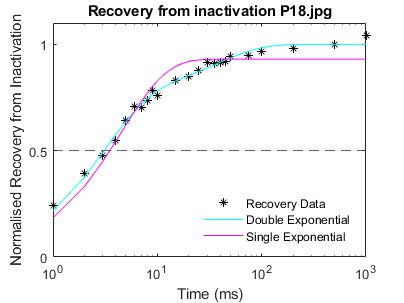

for wells = 1:1:n_wells(1)
    %try
    y1 = table2array(Peaks_Pall_filterM2(wells,:)) ;
    y1 = y1' 
    
    Y = fittype('Y0+ ((Plateau-Y0)*(100-PercentFast)*.01)*(1-exp(-KSlow*x)) + ((Plateau-Y0)*PercentFast*.01)*(1-exp(-KFast*x))') ;
    [DXfittedcurve,DXfitdata] = fit(time,y1,Y,'StartPoint',[0.5,0.05,1,0,0],'lower',[0,0,0,0,0], 'upper',[inf,inf,inf,inf,0]) 

    DXci = confint(DXfittedcurve,0.95) % some cells have unstable calculations (esp BrS variants with extemely long recoveries that cannot be plotted accurately. Matlab still gives a value but the CI will show as inf. This is added so that if inf is given anyywhere, then a single exp is used isntead.
    DXcii = find(DXci ==inf)
    
    singleY = fittype('Y0 + (Plateau-Y0)*(1-exp(-K*x))') 
    [SXfittedcurve,SXfitdata] = fit(time,y1,singleY,'StartPoint',[0.05,1,0],'lower',[0,0,0], 'upper',[inf,inf,0]) 

%    if DXcii >=1
    SXfitdata_K = [SXfitdata_K; SXfittedcurve.K] ;
    SXfitdata_adjR2 = [SXfitdata_adjR2; SXfitdata.adjrsquare] ;
    Tau = 1/SXfittedcurve.K ;
    SXfitdata_Tau = [SXfitdata_Tau; Tau] ;
    SXHalftime = (log(2))/(SXfittedcurve.K) ;
    SXfitdata_HalfTimes = [SXfitdata_HalfTimes;SXHalftime] ;

%    else 
    DXfitdata_KFast = [DXfitdata_KFast; DXfittedcurve.KFast] ;
    DXfitdata_KSlow = [DXfitdata_KSlow; DXfittedcurve.KSlow] ;
    DXfitdata_adjR2 = [DXfitdata_adjR2; DXfitdata.adjrsquare] ;
    TauFast = 1/DXfittedcurve.KFast ;
    TauSlow = 1/DXfittedcurve.KSlow ;
    DXfitdata_TauFast = [DXfitdata_TauFast; TauFast] ;
    DXfitdata_TauSlow = [DXfitdata_TauSlow; TauSlow] ;
    DXHalftime = (log(2)/(DXfittedcurve.KFast * (DXfittedcurve.PercentFast/100))) + (log(2)/(DXfittedcurve.KSlow * (1-DXfittedcurve.PercentFast/100))) ;
    DXfitdata_HalfTimes = [DXfitdata_HalfTimes;DXHalftime] ;
%    end




    clf
    plot(DXfittedcurve,'c',time,y1,'*k') 
    hold on
    plot(SXfittedcurve,'m') 
    
    set(gca,'Xscale','log') ;
    xlabel("Time (ms)") ;
    ylabel("Normalised Recovery from Inactivation") ;
    yline(0.5,'--') ;
    ylim([0,1.1]) ;
    yticks(0:0.5:1) ;
    titleWell = string(Peaks_Pall_filterM2.Properties.RowNames(wells)) ; 
    titleWell = strcat("Recovery from inactivation ",titleWell,".jpg") ;
    title(titleWell);
    
    legend("Recovery Data", "Double Exponential","Single Exponential","Location","southeast") ;
    legend("boxoff") ;
    hold off

    pid = fullfile(Parent_dir,Exp_dir,Protocol_dir(1),recoveries_dir,'RecoveryPlots\',titleWell) ;
    exportgraphics(gca,pid)



 % Try and catch eventually removed. if cannot plot on double exp, it
 % should plot on single.
  %  catch % try and catch is employed so that if a dataset cannot be fitted (bad cell resulting in poor values, e.g. poor initial values), the data is replaced with 0 so to not disrupt #wells and removed later
  %  DXfitdata_KFast = [DXfitdata_KFast; 0] ;
  %  DXfitdata_KSlow = [DXfitdata_KSlow; 0] ;
  %  DXfitdata_adjR2 = [DXfitdata_adjR2; 0] ;

  %  DXfitdata_TauFast = [DXfitdata_TauFast; 0] ;
  %  DXfitdata_TauSlow = [DXfitdata_TauSlow; 0] ;

  %  DXfitdata_HalfTimes = [DXfitdata_HalfTimes;0] ;

  %  end

end


%Turning into tables for tracking row names and variant IDs
alpcomp = [] ;
numcomp = [] ;
for i = 1:n_wells(1)
wellIDs = char(Peaks_Pall_filterM2.Properties.RowNames(i)) ;
alp = wellIDs(1) ;
num = wellIDs(2:3) ;
alpcomp = [alpcomp;alp] ;
numcomp = [numcomp;num] ;
end

DXfitfull = table(DXfitdata_KFast) ;
DXfitfull.dXKSlow = DXfitdata_KSlow ;
DXfitfull.dXTauFast = DXfitdata_TauFast ;
DXfitfull.dXTauSlow = DXfitdata_TauSlow ;
DXfitfull.dXHalfTime = DXfitdata_HalfTimes ;
DXfitfull.dXR2 = DXfitdata_adjR2 ;

DXfitfull.sXK = SXfitdata_K ;
DXfitfull.sXTau = SXfitdata_Tau ;
DXfitfull.sXHalfTime = SXfitdata_HalfTimes ;
DXfitfull.sXR2 = SXfitdata_adjR2 ;


DXfitfull.Properties.RowNames = Peaks_Pall_filterM2.Properties.RowNames

DXfitfull = 86×10 table
           DXfitdata_KFast     dXKSlow     dXTauFast    dXTauSlow    dXHalfTime     dXR2         sXK       sXTau     sXHalfTime     sXR2  
           _______________    _________    _________    _________    __________    _______    _________    ______    __________    _______

    A07         0.11439       0.0069397      8.7417       144.1        436.88      0.99758     0.089627    11.157      7.7337       0.9726
    A08          27.128        0.036794    0.036862      27.178        22.324      0.95955     0.058012    17.238      11.948      0.92878
    A10          10.353     

DXfitfull.WellID1 = alpcomp ;
DXfitfull.WellID2 = numcomp ;

DXfitfull = sortrows(DXfitfull,[12,11],{'ascend','ascend'})

DXfitfull = 86×12 table
           DXfitdata_KFast     dXKSlow     dXTauFast    dXTauSlow    dXHalfTime     dXR2        sXK       sXTau     sXHalfTime     sXR2      WellID1    WellID2
           _______________    _________    _________    _________    __________    _______    ________    ______    __________    _______    _______    _______

    O02        0.45166         0.027541       2.214      36.309        49.433      0.99203     0.12705     7.871      5.4558      0.86564       O         02   
    A07        0.11439        0.0069397      8.7417  

DXfitfull(:,11:12) = []

DXfitfull = 86×10 table
           DXfitdata_KFast     dXKSlow     dXTauFast    dXTauSlow    dXHalfTime     dXR2        sXK       sXTau     sXHalfTime     sXR2  
           _______________    _________    _________    _________    __________    _______    ________    ______    __________    _______

    O02        0.45166         0.027541       2.214      36.309        49.433      0.99203     0.12705     7.871      5.4558      0.86564
    A07        0.11439        0.0069397      8.7417       144.1        436.88      0.99758    0.089627    11.157      7.7337       0.9726
    B07        0.11943         0


toremove = find(DXfitfull.dXR2 <= 0.9) % remove failed/bad fit wells

toremove = 35

DXfitfull(toremove,:) = []

DXfitfull = 85×10 table
           DXfitdata_KFast     dXKSlow     dXTauFast    dXTauSlow    dXHalfTime     dXR2        sXK       sXTau     sXHalfTime     sXR2  
           _______________    _________    _________    _________    __________    _______    ________    ______    __________    _______

    O02        0.45166         0.027541       2.214      36.309        49.433      0.99203     0.12705     7.871      5.4558      0.86564
    A07        0.11439        0.0069397      8.7417       144.1        436.88      0.99758    0.089627    11.157      7.7337       0.9726
    B07        0.11943         0


% Add Variant ID

QCWells_filter1_2_3_4 = QCWells_filter1_2_3_4(contains(QCWells_filter1_2_3_4.Properties.RowNames,DXfitfull.Properties.RowNames),:)

QCWells_filter1_2_3_4 = 85×8 table
           WellID        CellType         SealResistance    Capacitance    SeriesResistance    SealResistance1    Capacitance1    SeriesResistance1
           ______    _________________    ______________    ___________    ________________    _______________    ____________    _________________

    O02    "O02"     SCN5A_DelQ1077_WT      3.6188e+09       1.829e-11        1.0188e+07         3.0212e+09        1.8322e-11        1.0334e+07    
    A07    "A07"     SCN5A_L618F            7.1298e+09      6.8291e-12        1.1414e+07         7.2072e+09        6.8216e-12        1.1396e+07    
    B07    "B07"     SCN5A_L618F            3.312

DXfitfull.Variant = QCWells_filter1_2_3_4.CellType

DXfitfull = 85×11 table
           DXfitdata_KFast     dXKSlow     dXTauFast    dXTauSlow    dXHalfTime     dXR2        sXK       sXTau     sXHalfTime     sXR2           Variant     
           _______________    _________    _________    _________    __________    _______    ________    ______    __________    _______    _________________

    O02        0.45166         0.027541       2.214      36.309        49.433      0.99203     0.12705     7.871      5.4558      0.86564    SCN5A_DelQ1077_WT
    A07        0.11439        0.0069397      8.7417       144.1        436.88      0.99758




DXfitfull_summ = groupsummary(DXfitfull,"Variant","mean")

DXfitfull_summ = 9×12 table
         Variant         GroupCount    mean_DXfitdata_KFast    mean_dXKSlow    mean_dXTauFast    mean_dXTauSlow    mean_dXHalfTime    mean_dXR2    mean_sXK     mean_sXTau    mean_sXHalfTime    mean_sXR2
    _________________    __________    ____________________    ____________    ______________    ______________    _______________    _________    _________    __________    _______________    _________

    SCN5A_DelQ1077_WT         1              0.45166             0.027541            2.214           36.309            49.433          0.99203       0.12705 

DXfitfull_summ.Properties.RowNames = string(DXfitfull_summ.Variant)

DXfitfull_summ = 9×12 table
                              Variant         GroupCount    mean_DXfitdata_KFast    mean_dXKSlow    mean_dXTauFast    mean_dXTauSlow    mean_dXHalfTime    mean_dXR2    mean_sXK     mean_sXTau    mean_sXHalfTime    mean_sXR2
                         _________________    __________    ____________________    ____________    ______________    ______________    _______________    _________    _________    __________    _______________    _________

    SCN5A_DelQ1077_WT    SCN5A_DelQ1077_WT         1              0.45166             0.027541    

HalfTimeNORM = DXfitfull_summ{'SCN5A_DelQ1077_WT', 'mean_sXHalfTime'}

HalfTimeNORM = 5.4558


DXfitfull.sXHTsubWTmean = DXfitfull.sXHalfTime-HalfTimeNORM

DXfitfull = 85×12 table
           DXfitdata_KFast     dXKSlow     dXTauFast    dXTauSlow    dXHalfTime     dXR2        sXK       sXTau     sXHalfTime     sXR2           Variant         sXHTsubWTmean
           _______________    _________    _________    _________    __________    _______    ________    ______    __________    _______    _________________    _____________

    O02        0.45166         0.027541       2.214      36.309        49.433      0.99203     0.12705     7.871      5.4558      0.86564    SCN5A_DelQ1077_WT             0   
    A07

%Exporting
DXfitfull = movevars(DXfitfull,"Variant","Before","DXfitdata_KFast")

DXfitfull = 85×12 table
                Variant         DXfitdata_KFast     dXKSlow     dXTauFast    dXTauSlow    dXHalfTime     dXR2        sXK       sXTau     sXHalfTime     sXR2      sXHTsubWTmean
           _________________    _______________    _________    _________    _________    __________    _______    ________    ______    __________    _______    _____________

    O02    SCN5A_DelQ1077_WT        0.45166         0.027541       2.214      36.309        49.433      0.99203     0.12705     7.871      5.4558      0.86564             0   
    A07

DXfitfull = movevars(DXfitfull,"sXHalfTime","After","Variant")

DXfitfull = 85×12 table
                Variant         sXHalfTime    DXfitdata_KFast     dXKSlow     dXTauFast    dXTauSlow    dXHalfTime     dXR2        sXK       sXTau      sXR2      sXHTsubWTmean
           _________________    __________    _______________    _________    _________    _________    __________    _______    ________    ______    _______    _____________

    O02    SCN5A_DelQ1077_WT      5.4558          0.45166         0.027541       2.214      36.309        49.433      0.99203     0.12705     7.871    0.86564             0   
    A07

DXfitfull = movevars(DXfitfull,"sXHTsubWTmean","After","sXHalfTime")

DXfitfull = 85×12 table
                Variant         sXHalfTime    sXHTsubWTmean    DXfitdata_KFast     dXKSlow     dXTauFast    dXTauSlow    dXHalfTime     dXR2        sXK       sXTau      sXR2  
           _________________    __________    _____________    _______________    _________    _________    _________    __________    _______    ________    ______    _______

    O02    SCN5A_DelQ1077_WT      5.4558               0           0.45166         0.027541       2.214      36.309        49.433      0.99203     0.12705     7.871    0.86564
    A07



writetable(Peaks_Pall_filterM2,fullfile(folderdir,'NormalisedRecovery.csv'),"WriteRowNames",true,"WriteVariableNames",true) ;
writetable(DXfitfull,fullfile(folderdir,'HT_KF_KS_TF_TS.csv'),"WriteRowNames",true,"WriteVariableNames",true) ;
writetable(DXfitfull_summ,fullfile(folderdir,'Summary.csv'),"WriteRowNames",true,"WriteVariableNames",true) ;

clear
